load ryan3_data.mat
%load ryan3_model_FirstVd_RUL.mat

generate_model = true

generate_model = logical
   1


% generate_model = false
if generate_model == false
    load ryan3_model_FirstVd_RUL.mat
end

# 필요한 데이타 로딩

%% https://kr.mathworks.com/help/matlab/ref/load.html

load('ryan3_data.mat','x_trainValid_IcFirstFull_RUL','x_trainValid_VdFirst_RUL','y_trainValid_First_RUL')
%load('ryan3_data.mat','x_trainValid_IcFirstFull_RUL','x_trainValid_VdFirst_RUL','y_trainValid_First_RUL')



# 선형회귀 - 모델 생성


%% https://kr.mathworks.com/help/matlab/ref/load.html

mdl = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15 + x16 + x17 + x18 + x19 + x20

Estimated Coefficients:
                   Estimate      SE        tStat        pValue  
                   ________    _______    ________    __________

    (Intercept)      -4.981     4.5734     -1.0891       0.27914
    x1             -0.22484    0.21452     -1.0481       0.29752
    x2              -120.86      66.86     -1.8077      0.074156
    x3               189.38     185.32      1.0219        0.3097
    x4              -190.47     252.63    -0.75395       0.45294
    x5               263.12     304.68     0.86361       0.39021
    x6              -183.91     158.55       -1

ryan3_model_gen_FirstVd_RUL_desc = "ryan3_model_FirstVd_RUL"

% load('ryan3_data.mat','x_trainValid_IcFirstFull_RUL','x_trainValid_VdFirst_RUL','y_trainValid_First_RUL')

if generate_model

mdl = fitlm(x_trainValid_VdFirst_RUL,y_trainValid_First_RUL)

ryan3_model_gen_FirstVd_RUL_desc = "ryan3_model_FirstVd_RUL"
save('ryan3_model_FirstVd_RUL.mat','ryan3_model_gen_FirstVd_RUL_desc' )
save('ryan3_model_FirstVd_RUL.mat','mdl' ,'-append')

coeff =    -4.9810
   -0.2248
 -120.8591
  189.3769
 -190.4678
  263.1208
 -183.9117
 -286.6715
  334.4501
  321.3600


ans =     0.8398    0.9212    0.9058    0.8948    0.8845    0.8738    0.8626    0.8507    0.8373    0.8226    0.8061    0.7875    0.7661    0.7407    0.7071    0.6436    0.4177         0    0.0000    0.0000


end

# 선형회귀 - 예측 - 20

#### 전류 패턴에 따른 라이프 사이클 예측 - 100개가 아니 20개로 

#### 선형회귀 - 정규화 필요 없지만 정규화해도 된다. 다른 머신러닝 방법을 위해 정규화 된것을 사용하자.

coeff = mdl.Coefficients.Estimate

yhat_trainValid =     0.0775
    0.0465
    0.0056
   -0.0466
    0.0882
   -0.0487
   -0.0628
    0.0361
    0.0589
    0.0979


x_trainValid_VdFirst_RUL(1,:)

training set 에서는 정말 잘 동작함.

RMSE 가 정말 작다.

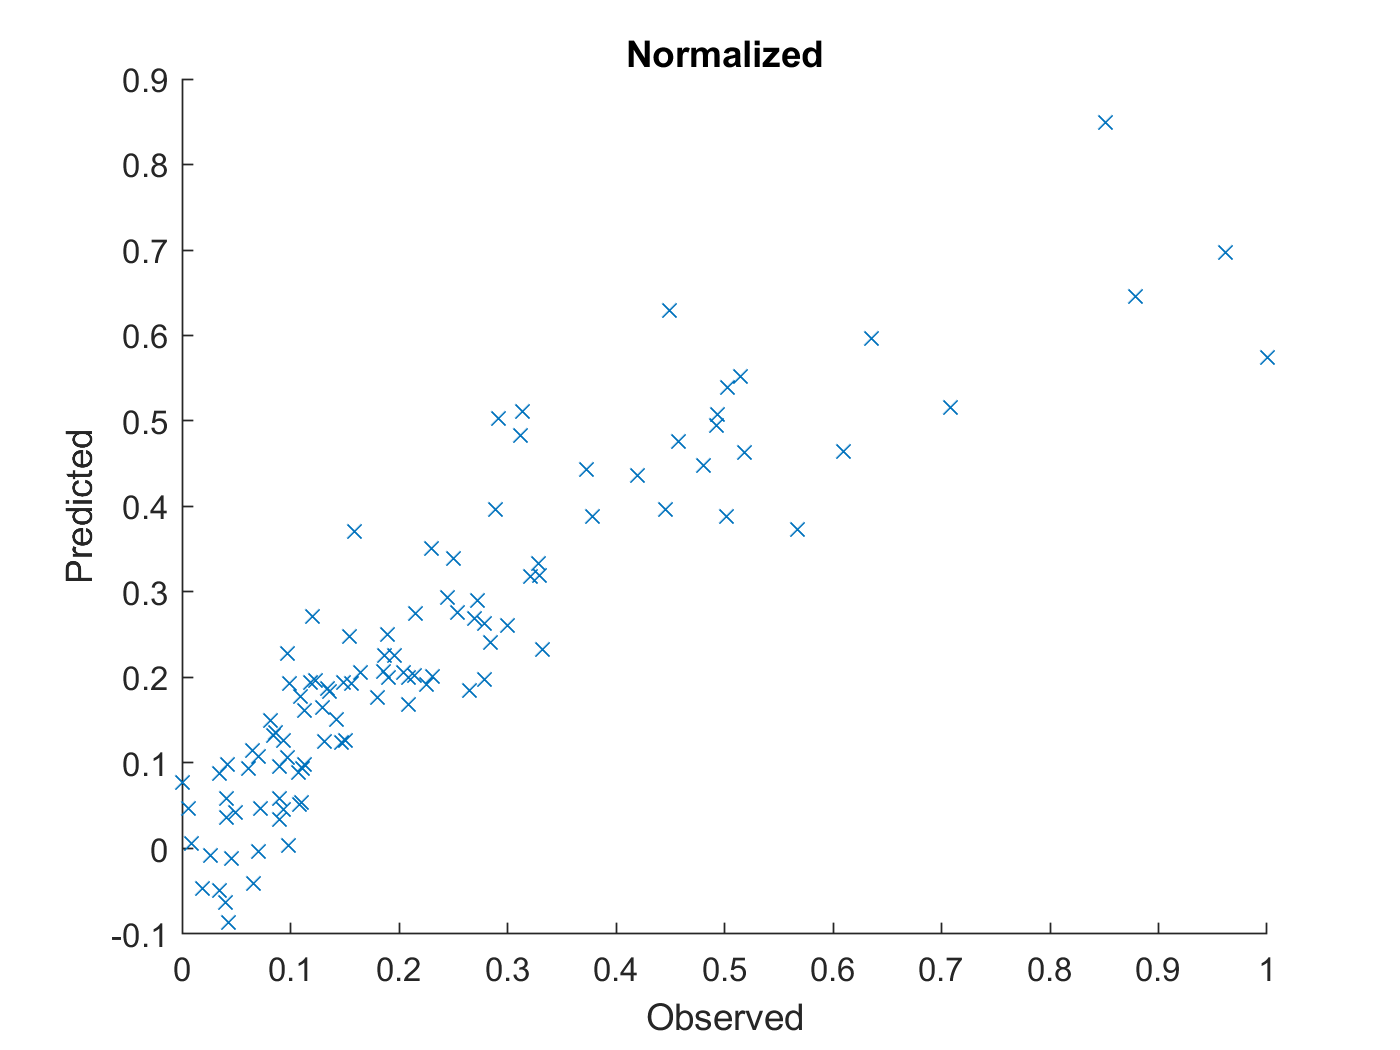

yhat_trainValid = x_trainValid_VdFirst_RUL*coeff(2:21)+coeff(1)

figure
hold on
plot(y_trainValid_First_RUL,yhat_trainValid,'x')
xlabel("Observed")
ylabel("Predicted")

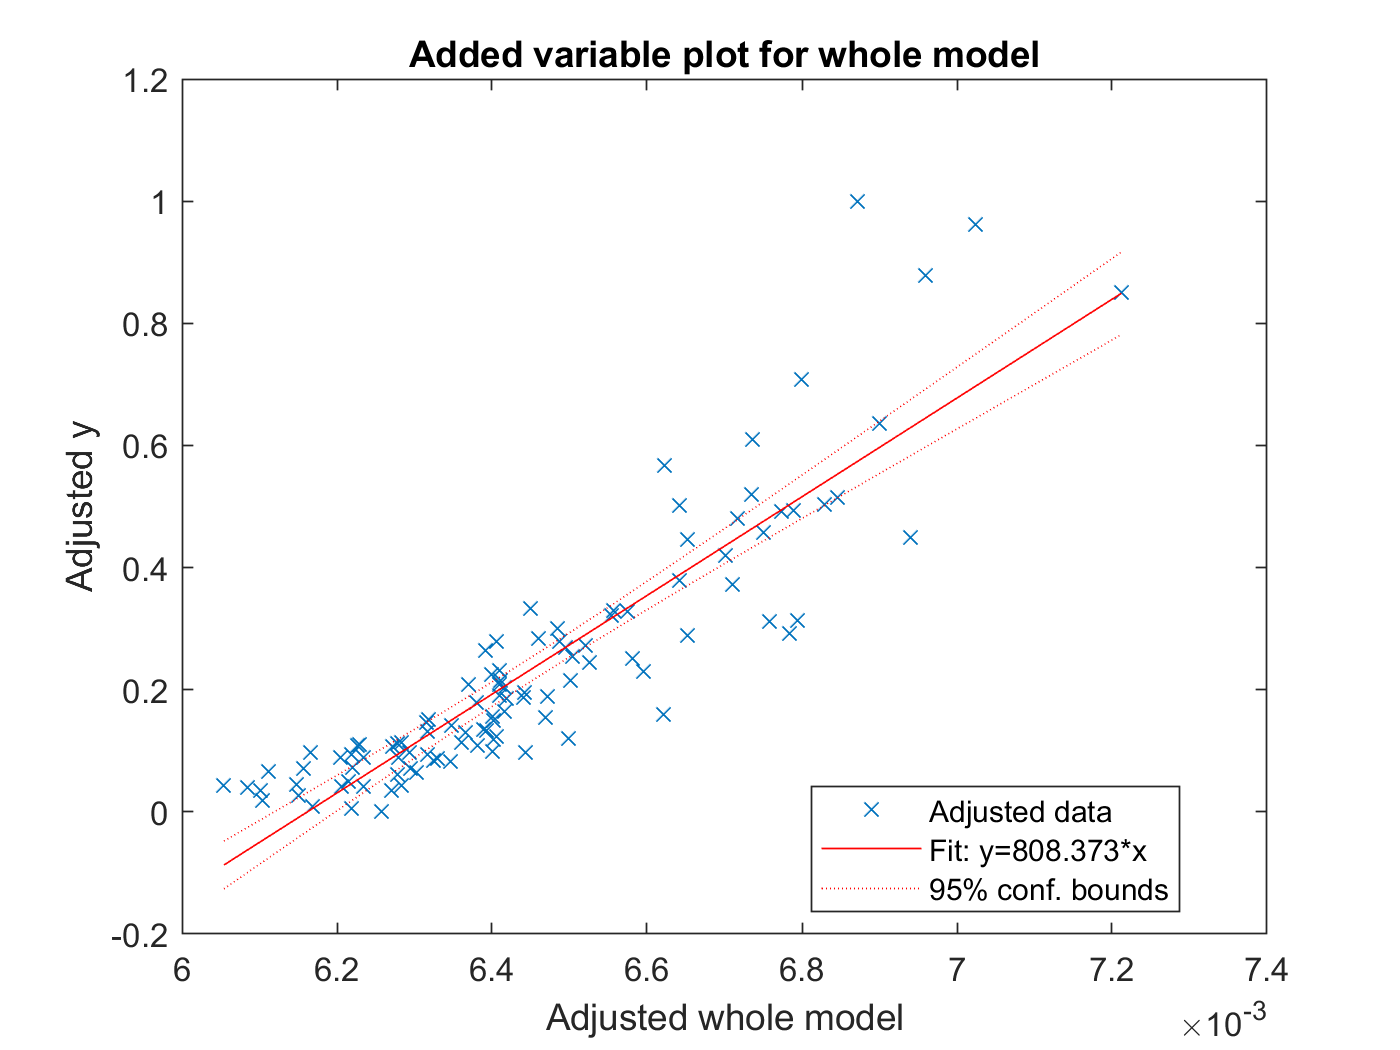

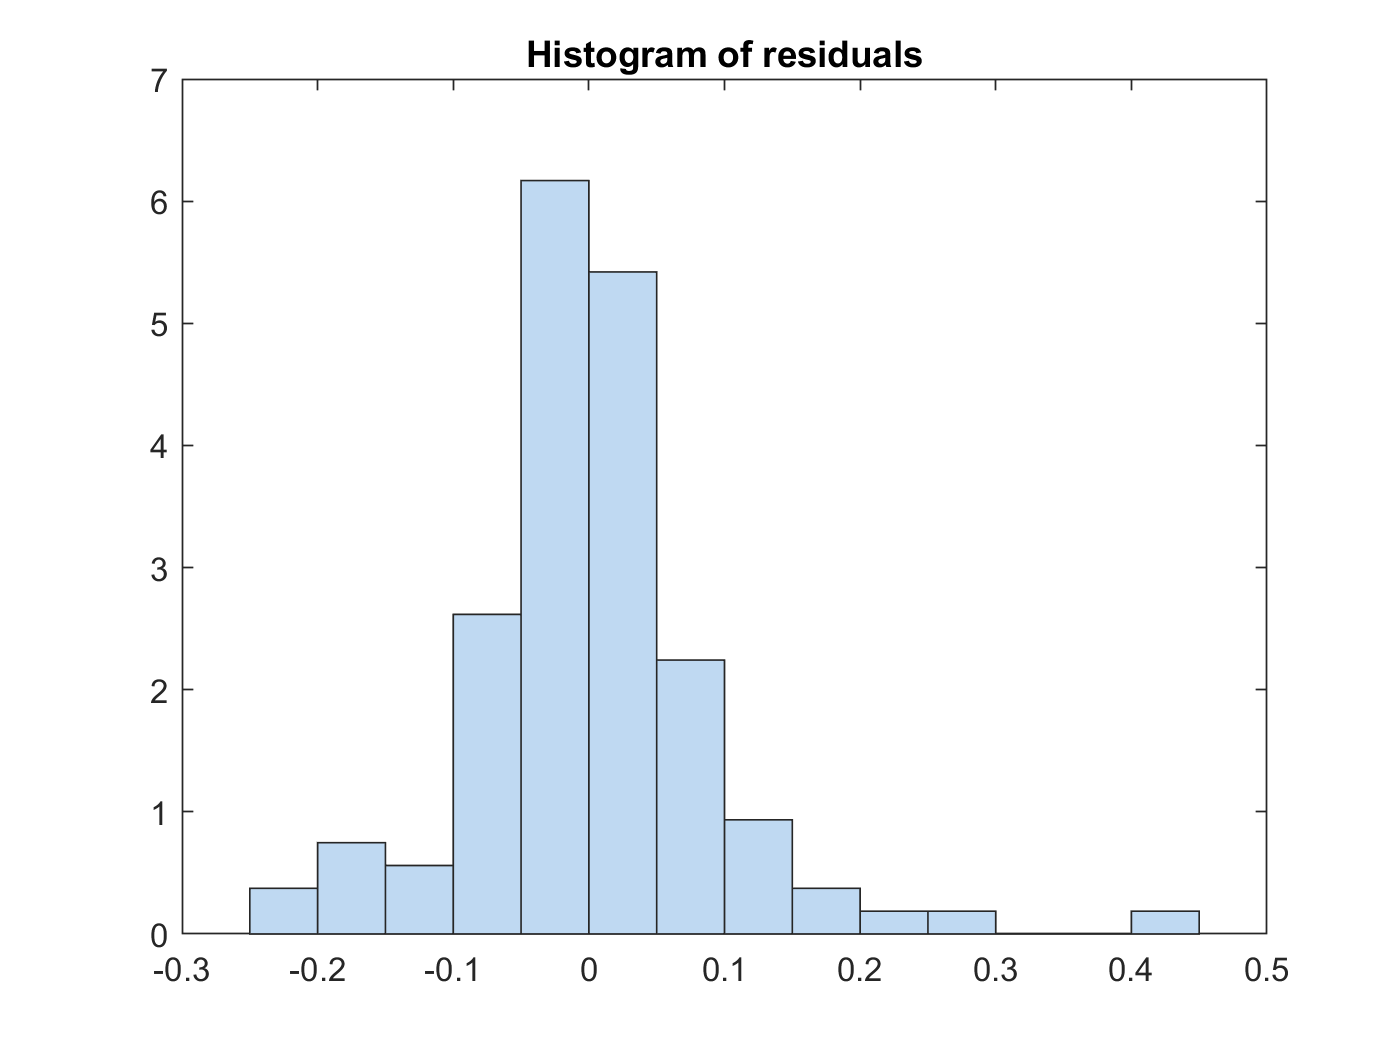

hold off
title 'Normalized'

%capHat = Ic(1)

plot(mdl)
plotResiduals(mdl)

# 선형회귀 - 예측 - 20

% yfit_trainValid = predict(mdl,Ic)

yfit_trainValid =     0.0775
    0.0465
    0.0056
   -0.0466
    0.0882
   -0.0487
   -0.0628
    0.0361
    0.0589
    0.0979


yfit_trainValid = predict(mdl,x_trainValid_VdFirst_RUL)

yfit_test =    -0.0586
    0.0493
    0.1143
    0.0844
    0.0935
    0.1811
    0.1734
    0.3089
    0.2794
    0.6888


yfit_test = predict(mdl,x_test_VdFirst_RUL)



y_trainValid =          0
    0.0056
    0.0085
    0.0188
    0.0348
    0.0348
    0.0405
    0.0414
    0.0414
    0.0424


y_trainValid= y_trainValid_First_RUL

y_test_VdFirst_RUL =     0.0292
    0.0556
    0.0885
    0.1064
    0.1224
    0.1516
    0.1949
    0.2316
    0.2872
    0.3719


y_test_VdFirst_RUL

# denormaize


yfit_trainValid = yfit_trainValid * yrate_First_RUL + ymin_First_RUL;
y_trainValid = y_trainValid * yrate_First_RUL + ymin_First_RUL;
yfit_test = yfit_test * yrate_First_RUL + ymin_First_RUL;
%Y_test_VdFirst_RUL = y_test_VdFirst_RUL * yrate_First_RUL + ymin_First_RUL;


MAE = mean(abs(yfit_trainValid-y_trainValid))

MAE = 67.2689

adjMAE = MAE/range(y_trainValid)

adjMAE = 0.0633

range(y_trainValid) % y_trainValid = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 1062


(y_trainValid - yhat_trainValid)    % Errors

ans = 	1.0e+03 *

    0.1089
    0.1150
    0.1180
    0.1290
    0.1459
    0.1460
    0.1521
    0.1530
    0.1529
    0.1539


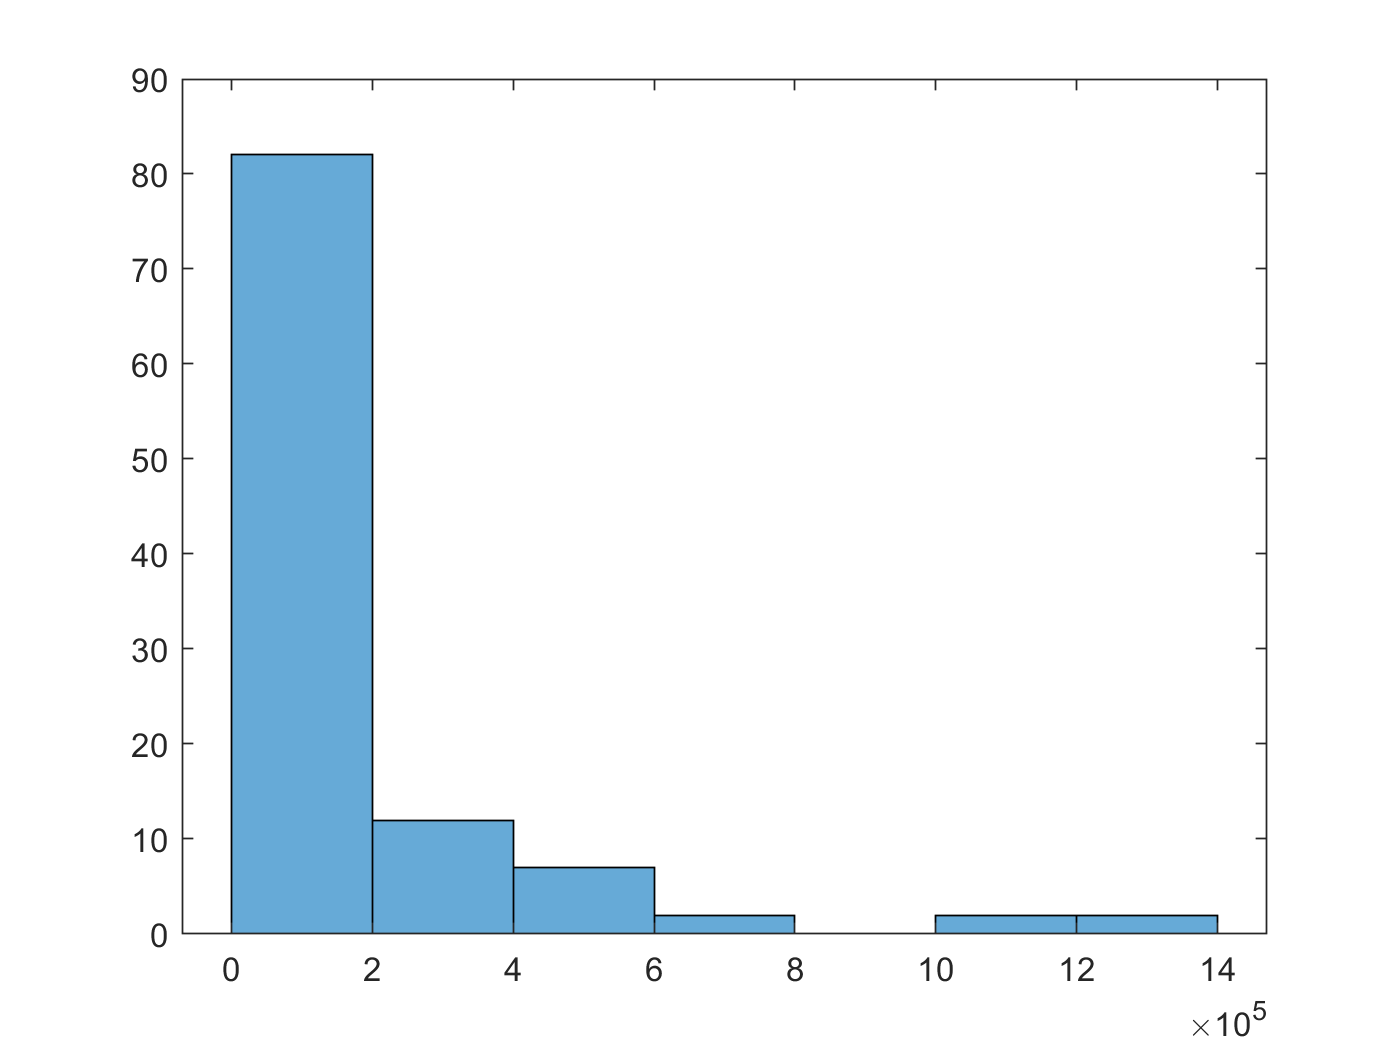

(y_trainValid - yhat_trainValid).^2;   % Squared Error
histogram((y_trainValid - yhat_trainValid).^2)

mean((y_trainValid - yhat_trainValid).^2);   % Mean Squared Error
RMSE = sqrt(mean((y_trainValid - yhat_trainValid).^2))  % Root Mean Squared Error

RMSE = 420.2523


RMSE_test = sqrt(mean((Y_test_VdFirst_RUL - yfit_test).^2))

RMSE_test = 133.2028

Y_test_VdFirst_RUL - yfit_test

ans =    93.2515
    6.6591
  -27.4029
   23.3190
   30.7365
  -31.3483
   22.8423
  -82.0403
    8.2985
 -336.4823


y_test_diff = horzcat(Y_test_VdFirst_RUL,(Y_test_VdFirst_RUL-yfit_test))

y_test_diff = 	1.0e+03 *

    0.1400    0.0933
    0.1680    0.0067
    0.2030   -0.0274
    0.2220    0.0233
    0.2390    0.0307
    0.2700   -0.0313
    0.3160    0.0228
    0.3550   -0.0820
    0.4140    0.0083
    0.5040   -0.3365


y_test_diff_percentage = abs(Y_test_VdFirst_RUL-yfit_test)./Y_test_VdFirst_RUL.*100

y_test_diff_percentage =    66.6082
    3.9638
   13.4989
   10.5040
   12.8605
   11.6105
    7.2286
   23.1100
    2.0045
   66.7624


y_test_diff_percentage_avg = sum(y_test_diff_percentage)/length(y_test_diff_percentage)

y_test_diff_percentage_avg = 21.6444

y_trainValid_diff = horzcat(y_trainValid,(y_trainValid-yfit_trainValid))

y_trainValid_diff = 	1.0e+03 *

    0.1090   -0.0823
    0.1150   -0.0434
    0.1180    0.0030
    0.1290    0.0695
    0.1460   -0.0566
    0.1460    0.0888
    0.1520    0.1097
    0.1530    0.0056
    0.1530   -0.0185
    0.1540   -0.0590


y_trainValid_diff_percentage = abs(y_trainValid-yfit_trainValid)./y_trainValid.*100

y_trainValid_diff_percentage =    75.5305
   37.7532
    2.5521
   53.8761
   38.7892
   60.7951
   72.1920
    3.6692
   12.1017
   38.2931


y_trainValid_diff_percentage_avg = sum(y_trainValid_diff_percentage)/length(y_trainValid_diff_percentage)

y_trainValid_diff_percentage_avg = 21.9181

num = 1:length(y_trainValid);
result_firstVd_RUL_linear = table(num',y_trainValid,(y_trainValid-yfit_trainValid),y_trainValid_diff_percentage);
result_firstVd_RUL_linear.Properties.VariableNames = {'bat num','RUL','오차','오차비율     '};
result_firstVd_RUL_linear

result_firstVd_RUL_linear = 107×4 table
    bat num    RUL     오차      오차비율     
    _______    ___    _______    ____________

       1       109    -82.328        75.53   
       2       115    -43.416       37.753   
       3       118     3.0115       2.5521   
       4       129       69.5       53.876   
       5       146    -56.632       38.789   
       6       146     88.761       60.795   
       7       152     109.73       72.192   
       8       153     5.6139       3.6692   
       9       153    -18.516       12.102   
      10       154    -58.971       38.293   
      11       155     138.38        89.28   
      12       157     59.874       38.137   
      13       174    -34.533       19.847   
      14       178    -52.273       29.367   
      15       179     113.37       63.337   
      16       184     79.052       42.963   


result_firstVd_RUL_linear_summary = table(RMSE_test,y_trainValid_diff_percentage_avg);
result_firstVd_RUL_linear_summary.Properties.VariableNames = {'RMSE','평균오차비율     '};
result_firstVd_RUL_linear_summary 

result_firstVd_RUL_linear_summary = 1×2 table
    RMSE     평균오차비율     
    _____    _______________

    133.2        21.918     


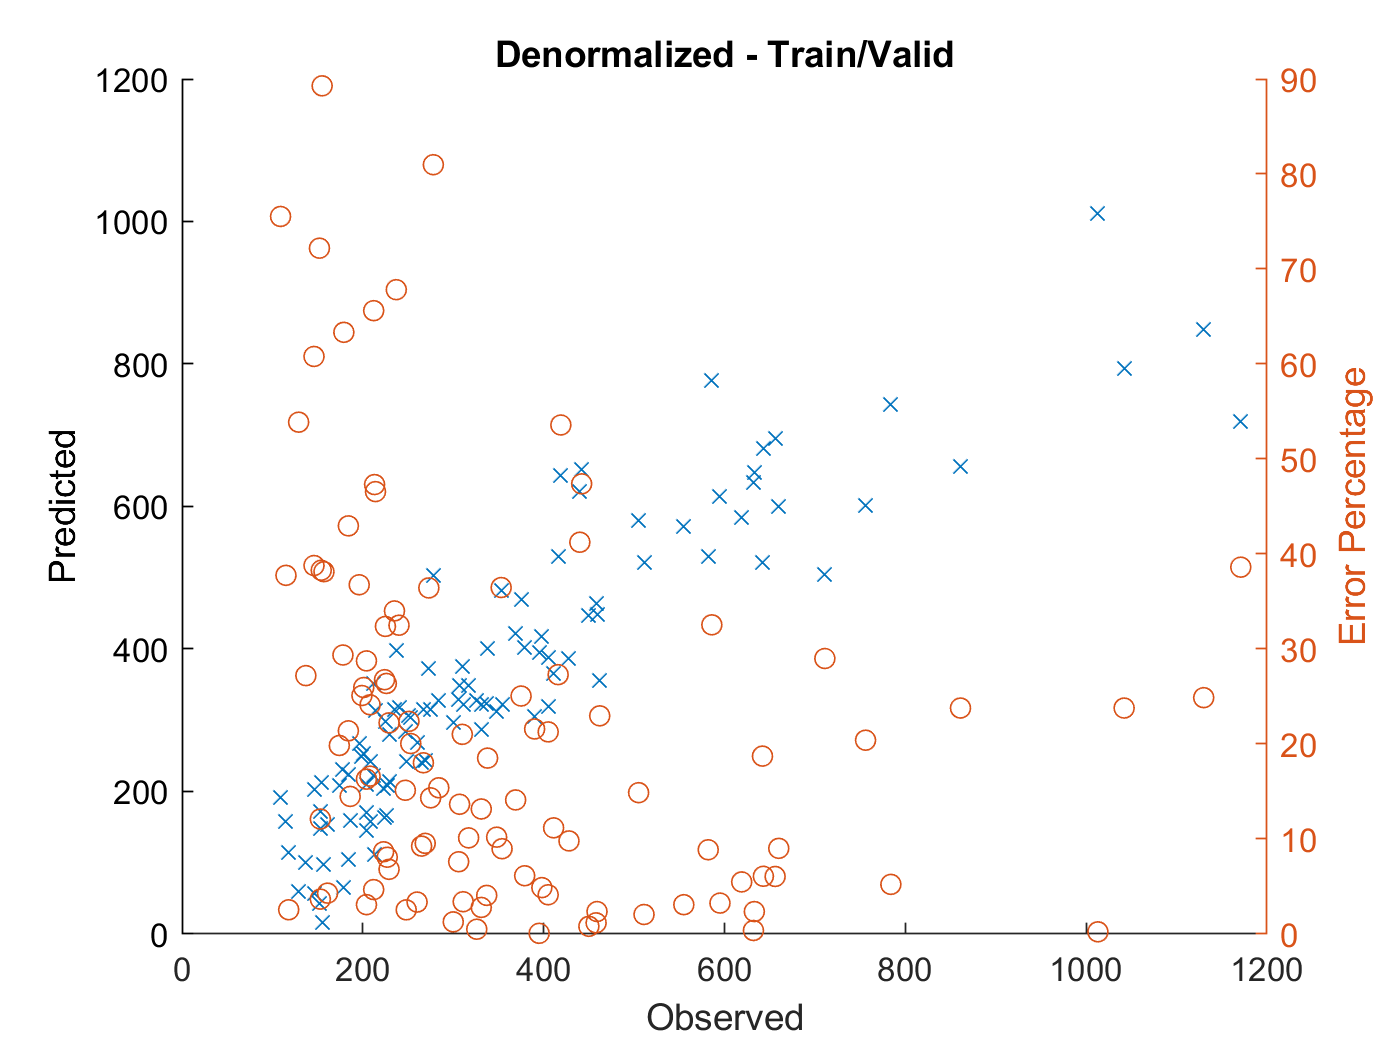


figure
hold on
plot(y_trainValid,yfit_trainValid,'x')
xlabel("Observed")
ylabel("Predicted")
xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage')
plot(y_trainValid,y_trainValid_diff_percentage,'o');

hold off
title 'Denormalized - Train/Valid'

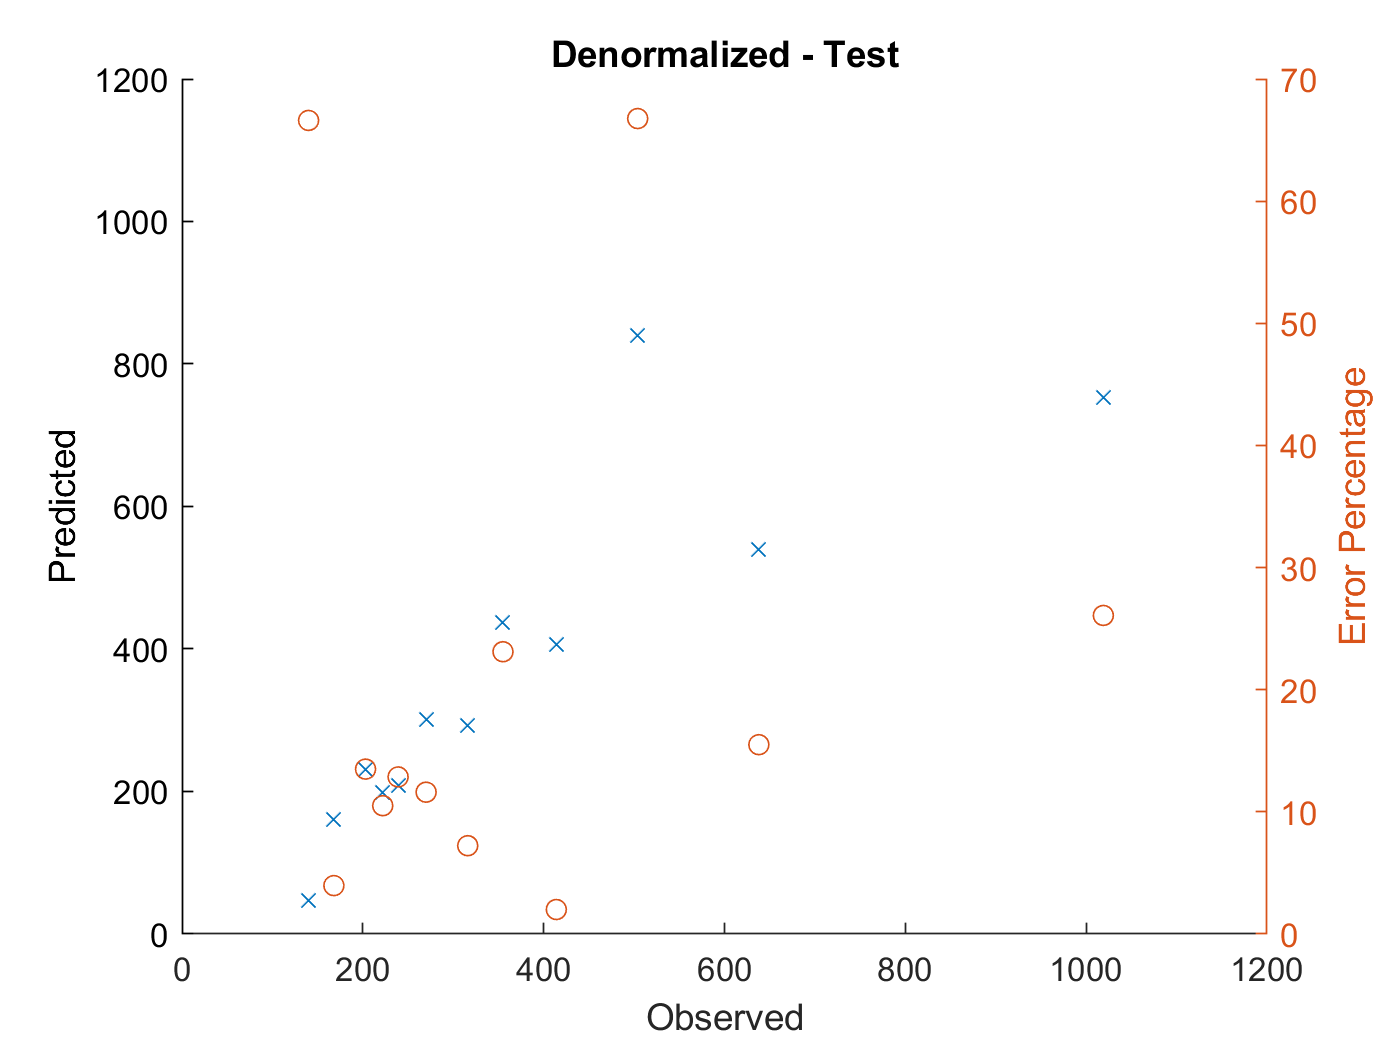


figure
hold on
plot(Y_test_VdFirst_RUL,yfit_test,'x')
xlabel("Observed")
ylabel("Predicted")
xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage')
plot(Y_test_VdFirst_RUL,y_test_diff_percentage,'o');

hold off
title 'Denormalized - Test'



% 테스트 셋에서는 예측이 전혀 안된다.


# FNN 학습 모델 생성

- netFNN1_1 = feedforwardnet(10);

- netFNN1_2 = feedforwardnet(20);

- netFNN1_3 = feedforwardnet(100);

- netFNN2_1 = feedforwardnet([20,20]);

- netFNN2_2 = feedforwardnet([100,20]);

- netFNN3_1 = feedforwardnet([20,20,20]);

- netFNN4_1 = feedforwardnet([20,20,20,20]);

- netFNN4_1 = feedforwardnet([20,20,20,20,20]);

- epoc = 300 

if generate_model
    

netFNN1_1 = feedforwardnet(10); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN1_1.divideFcn = 'divideind';
netFNN1_1.divideParam.trainInd = idxTrainRand;
netFNN1_1.divideParam.valInd = idxValidRand;
netFNN1_1.divideParam.testInd = idxTestRand; 
    
%netFNN1__1.divideParam
% https://kr.mathworks.com/matlabcentral/answers/314483-how-to-disable-popup-of-training-windows-for-neural-network-in-matlab
netFNN1_1.trainParam.showWindow = 0; 
netFNN1_1.trainParam.epochs = 300; % 전체 데이타를 300번 반복 이용해라
[netFNN1_1, tr] = train(netFNN1_1, xnorm_VdFirst_RUL', ynorm_VdFirst_RUL', 'useparallel',  'yes');
%tr

netFNN1_2 = feedforwardnet(20); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN1_2.divideFcn = 'divideind';

netFNN1_2.divideFcn = 'divideind';
netFNN1_2.divideParam.trainInd = idxTrainRand;
netFNN1_2.divideParam.valInd = idxValidRand;
netFNN1_2.divideParam.testInd = idxTestRand; 
    
%netFNN1_2.divideParam
netFNN1_2.trainParam.showWindow = 0; 
netFNN1_2.trainParam.epochs = 300; % 전체 데이타를 300번 반복 이용해라
netFNN1_2 = train(netFNN1_2, xnorm_VdFirst_RUL', ynorm_VdFirst_RUL', 'useparallel',  'yes');


netFNN1_3 = feedforwardnet(100); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN1_3.divideFcn = 'divideind';

netFNN1_3.divideFcn = 'divideind';
netFNN1_3.divideParam.trainInd = idxTrainRand;
netFNN1_3.divideParam.valInd = idxValidRand;
netFNN1_3.divideParam.testInd = idxTestRand; 
    
%netFNN1_3.divideParam
netFNN1_3.trainParam.showWindow = 0; 
netFNN1_3.trainParam.epochs = 300; % 전체 데이타를 300번 반복 이용해라
netFNN1_3 = train(netFNN1_3, xnorm_VdFirst_RUL', ynorm_VdFirst_RUL', 'useparallel',  'yes');


netFNN2_1 = feedforwardnet([20,20]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN2_1.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN2_1.divideParam.trainInd = tr.trainInd;
netFNN2_1.divideParam.valInd = tr.valInd;
netFNN2_1.divideParam.testInd = tr.testInd; 

netFNN2_1.trainParam.epochs = 300; %100; % 전체 데이타를 300번 반복 이용해라
netFNN2_1.trainParam.showWindow = 0;
netFNN2_1.trainParam.show = NaN;
netFNN2_1 = train(netFNN2_1, xnorm_VdFirst_RUL', ynorm_VdFirst_RUL', 'useparallel',  'yes');
%view(netFNN2_1)
%netFNN2_1
%tr2

netFNN2_2 = feedforwardnet([100,20]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN2_2.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN2_2.divideParam.trainInd = tr.trainInd;
netFNN2_2.divideParam.valInd = tr.valInd;
netFNN2_2.divideParam.testInd = tr.testInd; 

netFNN2_2.trainParam.epochs = 300; %100; % 전체 데이타를 300번 반복 이용해라
netFNN2_2.trainParam.show = NaN;
netFNN2_2.trainParam.showWindow = 0;
netFNN2_2 = train(netFNN2_1, xnorm_VdFirst_RUL', ynorm_VdFirst_RUL', 'useparallel',  'yes');
%view(netFNN2_1)
%netFNN2_1
%tr2

netFNN3_1 = feedforwardnet([20,20,20]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
% netFNN340.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent

netFNN3_1.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN3_1.divideParam.trainInd = tr.trainInd;
netFNN3_1.divideParam.valInd = tr.valInd;
netFNN3_1.divideParam.testInd = tr.testInd; 

netFNN3_1.trainParam.epochs = 300; %100; % 전체 데이타를 300번 반복 이용해라
netFNN3_1.trainParam.show = NaN;
netFNN3_1.trainParam.showWindow = 0;
netFNN3_1 = train(netFNN3_1, xnorm_VdFirst_RUL', ynorm_VdFirst_RUL', 'useparallel',  'yes');
%view(netFNN3_1)

netFNN4_1 = feedforwardnet([20,20,20,20]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
% netFNN340.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent

netFNN4_1.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN4_1.divideParam.trainInd = tr.trainInd;
netFNN4_1.divideParam.valInd = tr.valInd;
netFNN4_1.divideParam.testInd = tr.testInd; 

netFNN4_1.trainParam.epochs = 300; %100; % 전체 데이타를 300번 반복 이용해라
netFNN4_1.trainParam.show = NaN;
netFNN4_1.trainParam.showWindow = 0;
netFNN4_1 = train(netFNN3_1, xnorm_VdFirst_RUL', ynorm_VdFirst_RUL', 'useparallel',  'yes');
%view(netFNN3_1)

netFNN5_1 = feedforwardnet([20,20,20,20,20]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
% netFNN340.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent

netFNN5_1.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN5_1.divideParam.trainInd = tr.trainInd;
netFNN5_1.divideParam.valInd = tr.valInd;
netFNN5_1.divideParam.testInd = tr.testInd; 

netFNN5_1.trainParam.epochs = 300; %100; % 전체 데이타를 300번 반복 이용해라
netFNN5_1.trainParam.show = NaN;
netFNN5_1.trainParam.showWindow = 0;
netFNN5_1 = train(netFNN3_1, xnorm_VdFirst_RUL', ynorm_VdFirst_RUL', 'useparallel',  'yes');
%view(netFNN3_1)

save('ryan3_model_FirstVd_RUL.mat','netFNN1_1' ,'-append')
save('ryan3_model_FirstVd_RUL.mat','netFNN1_2' ,'-append')
save('ryan3_model_FirstVd_RUL.mat','netFNN1_3' ,'-append')
save('ryan3_model_FirstVd_RUL.mat','netFNN2_1' ,'-append')
save('ryan3_model_FirstVd_RUL.mat','netFNN2_2' ,'-append')
save('ryan3_model_FirstVd_RUL.mat','netFNN3_1' ,'-append')
save('ryan3_model_FirstVd_RUL.mat','netFNN4_1' ,'-append')
save('ryan3_model_FirstVd_RUL.mat','netFNN5_1' ,'-append')

end

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


# FNN 예측

pFNN1_1 = netFNN1_1(xnorm_VdFirst_RUL(idxTestSort, :)');
pFNN1_2 = netFNN1_2(xnorm_VdFirst_RUL(idxTestSort, :)');
pFNN1_3 = netFNN1_3(xnorm_VdFirst_RUL(idxTestSort, :)');
pFNN2_1 = netFNN2_1(xnorm_VdFirst_RUL(idxTestSort, :)');
pFNN2_2 = netFNN2_2(xnorm_VdFirst_RUL(idxTestSort, :)');
pFNN3_1 = netFNN3_1(xnorm_VdFirst_RUL(idxTestSort, :)');
pFNN4_1 = netFNN4_1(xnorm_VdFirst_RUL(idxTestSort, :)');
pFNN5_1 = netFNN5_1(xnorm_VdFirst_RUL(idxTestSort, :)');

ytest = ynorm_VdFirst_RUL(idxTestSort, :)*yrate_First_RUL + ymin_First_RUL;
pFNN1_1_hat = pFNN1_1 * yrate_First_RUL + ymin_First_RUL;
pFNN1_2_hat = pFNN1_2 * yrate_First_RUL + ymin_First_RUL;
pFNN1_3_hat = pFNN1_3 * yrate_First_RUL + ymin_First_RUL;
pFNN2_1_hat = pFNN2_1 * yrate_First_RUL + ymin_First_RUL;
pFNN2_2_hat = pFNN2_2 * yrate_First_RUL + ymin_First_RUL;
pFNN3_1_hat = pFNN3_1 * yrate_First_RUL + ymin_First_RUL;
pFNN4_1_hat = pFNN4_1 * yrate_First_RUL + ymin_First_RUL;
pFNN5_1_hat = pFNN5_1 * yrate_First_RUL + ymin_First_RUL;


rmse_pFNN1_1_hat = sqrt(mean(( ytest' - pFNN1_1_hat ).^2))

rmse_pFNN1_1_hat = 156.6996

rmse_pFNN1_2_hat = sqrt(mean(( ytest' - pFNN1_2_hat ).^2))

rmse_pFNN1_2_hat = 123.5353

rmse_pFNN1_3_hat = sqrt(mean(( ytest' - pFNN1_3_hat ).^2))

rmse_pFNN1_3_hat = 168.5199

rmse_pFNN2_1_hat = sqrt(mean(( ytest' - pFNN2_1_hat ).^2))

rmse_pFNN2_1_hat = 155.7731

rmse_pFNN2_2_hat = sqrt(mean(( ytest' - pFNN2_2_hat ).^2))

rmse_pFNN2_2_hat = 155.7731

rmse_pFNN3_1_hat = sqrt(mean(( ytest' - pFNN3_1_hat ).^2))

rmse_pFNN3_1_hat = 127.3525

rmse_pFNN4_1_hat = sqrt(mean(( ytest' - pFNN4_1_hat ).^2))

rmse_pFNN4_1_hat = 127.3525

rmse_pFNN5_1_hat = sqrt(mean(( ytest' - pFNN5_1_hat ).^2))

rmse_pFNN5_1_hat = 127.3525

y_test_diff_percentage_FNN1_1_hat_avg = sum(abs(Y_test_VdFirst_RUL'-pFNN1_1_hat)./Y_test_VdFirst_RUL'.*100)/length(abs(Y_test_VdFirst_RUL'-pFNN1_1_hat)./Y_test_VdFirst_RUL')

y_test_diff_percentage_FNN1_1_hat_avg = 47.5543

y_test_diff_percentage_FNN1_2_hat_avg = sum(abs(Y_test_VdFirst_RUL'-pFNN1_2_hat)./Y_test_VdFirst_RUL'.*100)/length(abs(Y_test_VdFirst_RUL'-pFNN1_2_hat)./Y_test_VdFirst_RUL')

y_test_diff_percentage_FNN1_2_hat_avg = 40.6281

y_test_diff_percentage_FNN1_3_hat_avg = sum(abs(Y_test_VdFirst_RUL'-pFNN1_3_hat)./Y_test_VdFirst_RUL'.*100)/length(abs(Y_test_VdFirst_RUL'-pFNN1_3_hat)./Y_test_VdFirst_RUL')

y_test_diff_percentage_FNN1_3_hat_avg = 48.0427

y_test_diff_percentage_FNN2_1_hat_avg = sum(abs(Y_test_VdFirst_RUL'-pFNN2_1_hat)./Y_test_VdFirst_RUL'.*100)/length(abs(Y_test_VdFirst_RUL'-pFNN2_1_hat)./Y_test_VdFirst_RUL')

y_test_diff_percentage_FNN2_1_hat_avg = 53.7419

y_test_diff_percentage_FNN2_2_hat_avg = sum(abs(Y_test_VdFirst_RUL'-pFNN2_2_hat)./Y_test_VdFirst_RUL'.*100)/length(abs(Y_test_VdFirst_RUL'-pFNN2_2_hat)./Y_test_VdFirst_RUL')

y_test_diff_percentage_FNN2_2_hat_avg = 53.7419

y_test_diff_percentage_FNN3_1_hat_avg = sum(abs(Y_test_VdFirst_RUL'-pFNN3_1_hat)./Y_test_VdFirst_RUL'.*100)/length(abs(Y_test_VdFirst_RUL'-pFNN3_1_hat)./Y_test_VdFirst_RUL')

y_test_diff_percentage_FNN3_1_hat_avg = 43.6774

y_test_diff_percentage_FNN4_1_hat_avg = sum(abs(Y_test_VdFirst_RUL'-pFNN4_1_hat)./Y_test_VdFirst_RUL'.*100)/length(abs(Y_test_VdFirst_RUL'-pFNN4_1_hat)./Y_test_VdFirst_RUL')

y_test_diff_percentage_FNN4_1_hat_avg = 43.6774

y_test_diff_percentage_FNN5_1_hat_avg = sum(abs(Y_test_VdFirst_RUL'-pFNN5_1_hat)./Y_test_VdFirst_RUL'.*100)/length(abs(Y_test_VdFirst_RUL'-pFNN5_1_hat)./Y_test_VdFirst_RUL')

y_test_diff_percentage_FNN5_1_hat_avg = 43.6774

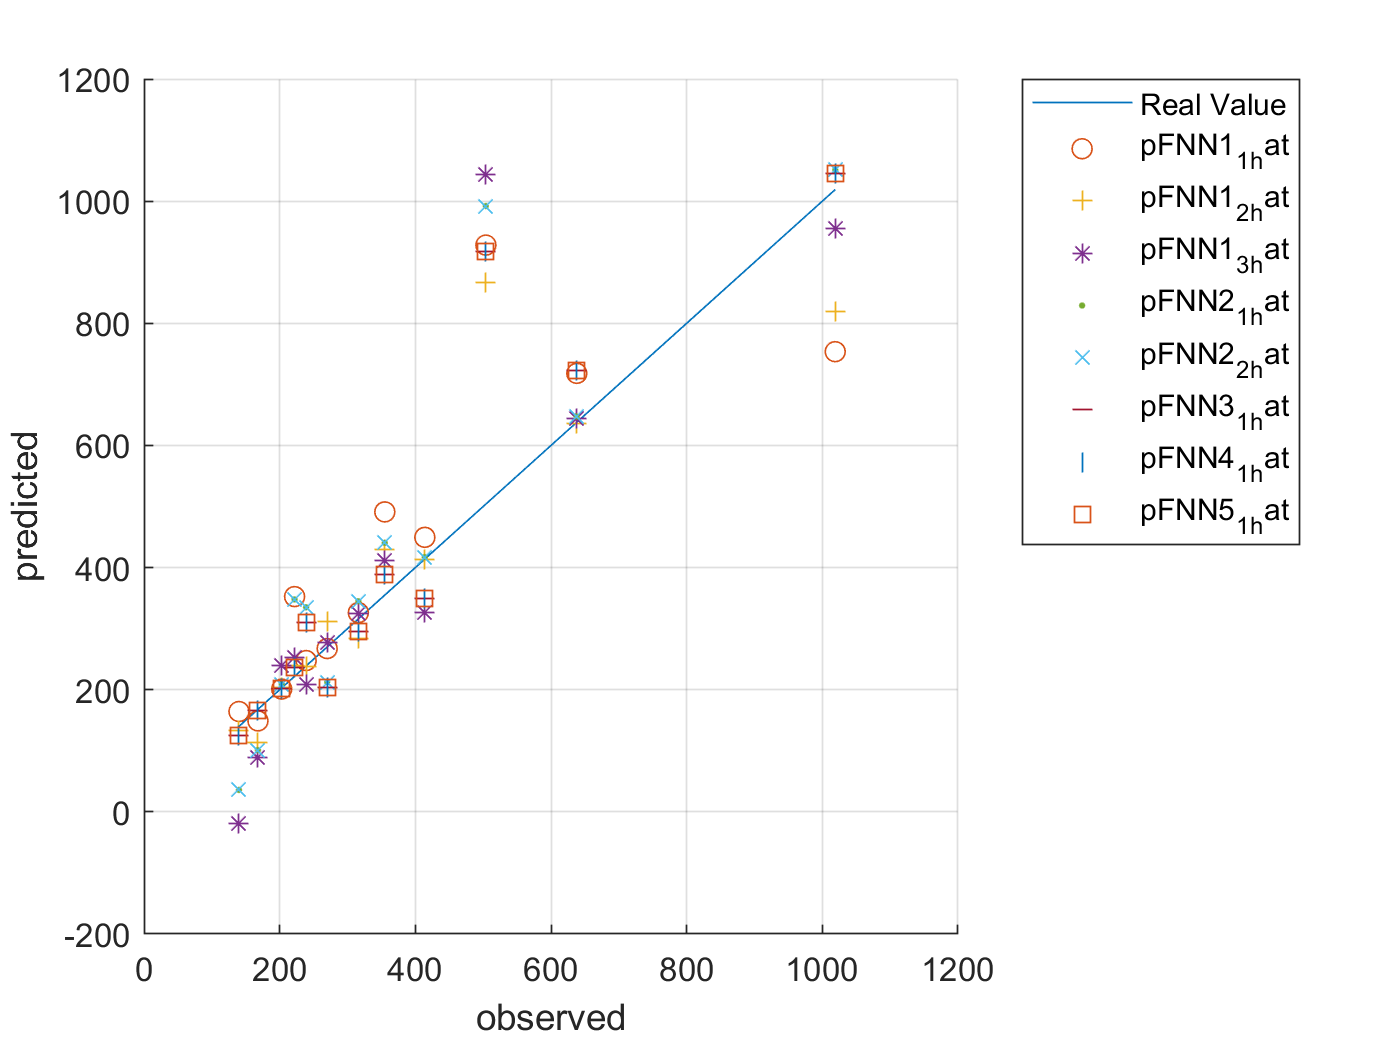



figure, hold on, grid on,
plot(ytest,ytest)
plot(ytest,pFNN1_1_hat,'o')
plot(ytest,pFNN1_2_hat,'+')
plot(ytest,pFNN1_3_hat,'*')
plot(ytest,pFNN2_1_hat,'.')
plot(ytest,pFNN2_2_hat,'x')
plot(ytest,pFNN3_1_hat,'_')
plot(ytest,pFNN4_1_hat,'|')
plot(ytest,pFNN5_1_hat,'s')
hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pFNN1_1_hat', ... 
		'pFNN1_2_hat', ...
		'pFNN1_3_hat', ... 	
		'pFNN2_1_hat', ... 
		'pFNN2_2_hat', ... 
		'pFNN3_1_hat', ... 
		'pFNN4_1_hat', ... 
		'pFNN5_1_hat','Location','northeastoutside')

pFNN1_1_self = netFNN1_1(xnorm_VdFirst_RUL([idxTrainSort idxValidSort], :)');
pFNN1_2_self = netFNN1_2(xnorm_VdFirst_RUL([idxTrainSort idxValidSort], :)');
pFNN1_3_self = netFNN1_3(xnorm_VdFirst_RUL([idxTrainSort idxValidSort], :)');
pFNN2_1_self = netFNN2_1(xnorm_VdFirst_RUL([idxTrainSort idxValidSort], :)');
pFNN2_2_self = netFNN2_2(xnorm_VdFirst_RUL([idxTrainSort idxValidSort], :)');
pFNN3_1_self = netFNN3_1(xnorm_VdFirst_RUL([idxTrainSort idxValidSort], :)');
pFNN4_1_self = netFNN4_1(xnorm_VdFirst_RUL([idxTrainSort idxValidSort], :)');
pFNN5_1_self = netFNN5_1(xnorm_VdFirst_RUL([idxTrainSort idxValidSort], :)');

ytrain_self = ynorm_VdFirst_RUL([idxTrainSort idxValidSort], :)*yrate_First_RUL + ymin_First_RUL;
pFNN1_1_self_hat = pFNN1_1_self * yrate_First_RUL + ymin_First_RUL;
pFNN1_2_self_hat = pFNN1_2_self * yrate_First_RUL + ymin_First_RUL;
pFNN1_3_self_hat = pFNN1_3_self * yrate_First_RUL + ymin_First_RUL;
pFNN2_1_self_hat = pFNN2_1_self * yrate_First_RUL + ymin_First_RUL;
pFNN2_2_self_hat = pFNN2_2_self * yrate_First_RUL + ymin_First_RUL;
pFNN3_1_self_hat = pFNN3_1_self * yrate_First_RUL + ymin_First_RUL;
pFNN4_1_self_hat = pFNN4_1_self * yrate_First_RUL + ymin_First_RUL;
pFNN5_1_self_hat = pFNN5_1_self * yrate_First_RUL + ymin_First_RUL;


rmse_pFNN1_1_self_hat = sqrt(mean(( ytrain_self' - pFNN1_1_self_hat ).^2))

rmse_pFNN1_1_self_hat = 114.5482

rmse_pFNN1_2_self_hat = sqrt(mean(( ytrain_self' - pFNN1_2_self_hat ).^2))

rmse_pFNN1_2_self_hat = 106.6485

rmse_pFNN1_3_self_hat = sqrt(mean(( ytrain_self' - pFNN1_3_self_hat ).^2))

rmse_pFNN1_3_self_hat = 31.1146

rmse_pFNN2_1_self_hat = sqrt(mean(( ytrain_self' - pFNN2_1_self_hat ).^2))

rmse_pFNN2_1_self_hat = 120.1335

rmse_pFNN2_2_self_hat = sqrt(mean(( ytrain_self' - pFNN2_2_self_hat ).^2))

rmse_pFNN2_2_self_hat = 120.1335

rmse_pFNN3_1_self_hat = sqrt(mean(( ytrain_self' - pFNN3_1_self_hat ).^2))

rmse_pFNN3_1_self_hat = 141.1882

rmse_pFNN4_1_self_hat = sqrt(mean(( ytrain_self' - pFNN4_1_self_hat ).^2))

rmse_pFNN4_1_self_hat = 141.1882

rmse_pFNN5_1_self_hat = sqrt(mean(( ytrain_self' - pFNN5_1_self_hat ).^2))

rmse_pFNN5_1_self_hat = 141.1882

y_test_diff_percentage_FNN1_1_self_hat_avg = sum(abs(ytrain_self'-pFNN1_1_self_hat)./ytrain_self'.*100)/length(abs(ytrain_self'-pFNN1_1_self_hat)./ytrain_self')

y_test_diff_percentage_FNN1_1_self_hat_avg = 21.0086

ytrain_self_diff_percentage_FNN1_2_self_hat_avg = sum(abs(ytrain_self'-pFNN1_2_self_hat)./ytrain_self'.*100)/length(abs(ytrain_self'-pFNN1_2_self_hat)./ytrain_self')

ytrain_self_diff_percentage_FNN1_2_self_hat_avg = 14.0245

ytrain_self_diff_percentage_FNN1_3_self_hat_avg = sum(abs(ytrain_self'-pFNN1_3_self_hat)./ytrain_self'.*100)/length(abs(ytrain_self'-pFNN1_3_self_hat)./ytrain_self')

ytrain_self_diff_percentage_FNN1_3_self_hat_avg = 4.3654

ytrain_self_diff_percentage_FNN2_1_self_hat_avg = sum(abs(ytrain_self'-pFNN2_1_self_hat)./ytrain_self'.*100)/length(abs(ytrain_self'-pFNN2_1_self_hat)./ytrain_self')

ytrain_self_diff_percentage_FNN2_1_self_hat_avg = 24.1523

ytrain_self_diff_percentage_FNN2_2_self_hat_avg = sum(abs(ytrain_self'-pFNN2_2_self_hat)./ytrain_self'.*100)/length(abs(ytrain_self'-pFNN2_2_self_hat)./ytrain_self')

ytrain_self_diff_percentage_FNN2_2_self_hat_avg = 24.1523

ytrain_self_diff_percentage_FNN3_1_self_hat_avg = sum(abs(ytrain_self'-pFNN3_1_self_hat)./ytrain_self'.*100)/length(abs(ytrain_self'-pFNN3_1_self_hat)./ytrain_self')

ytrain_self_diff_percentage_FNN3_1_self_hat_avg = 13.0126

ytrain_self_diff_percentage_FNN4_1_self_hat_avg = sum(abs(ytrain_self'-pFNN4_1_self_hat)./ytrain_self'.*100)/length(abs(ytrain_self'-pFNN4_1_self_hat)./ytrain_self')

ytrain_self_diff_percentage_FNN4_1_self_hat_avg = 13.0126

ytrain_self_diff_percentage_FNN5_1_self_hat_avg = sum(abs(ytrain_self'-pFNN5_1_self_hat)./ytrain_self'.*100)/length(abs(ytrain_self'-pFNN5_1_self_hat)./ytrain_self')

ytrain_self_diff_percentage_FNN5_1_self_hat_avg = 13.0126

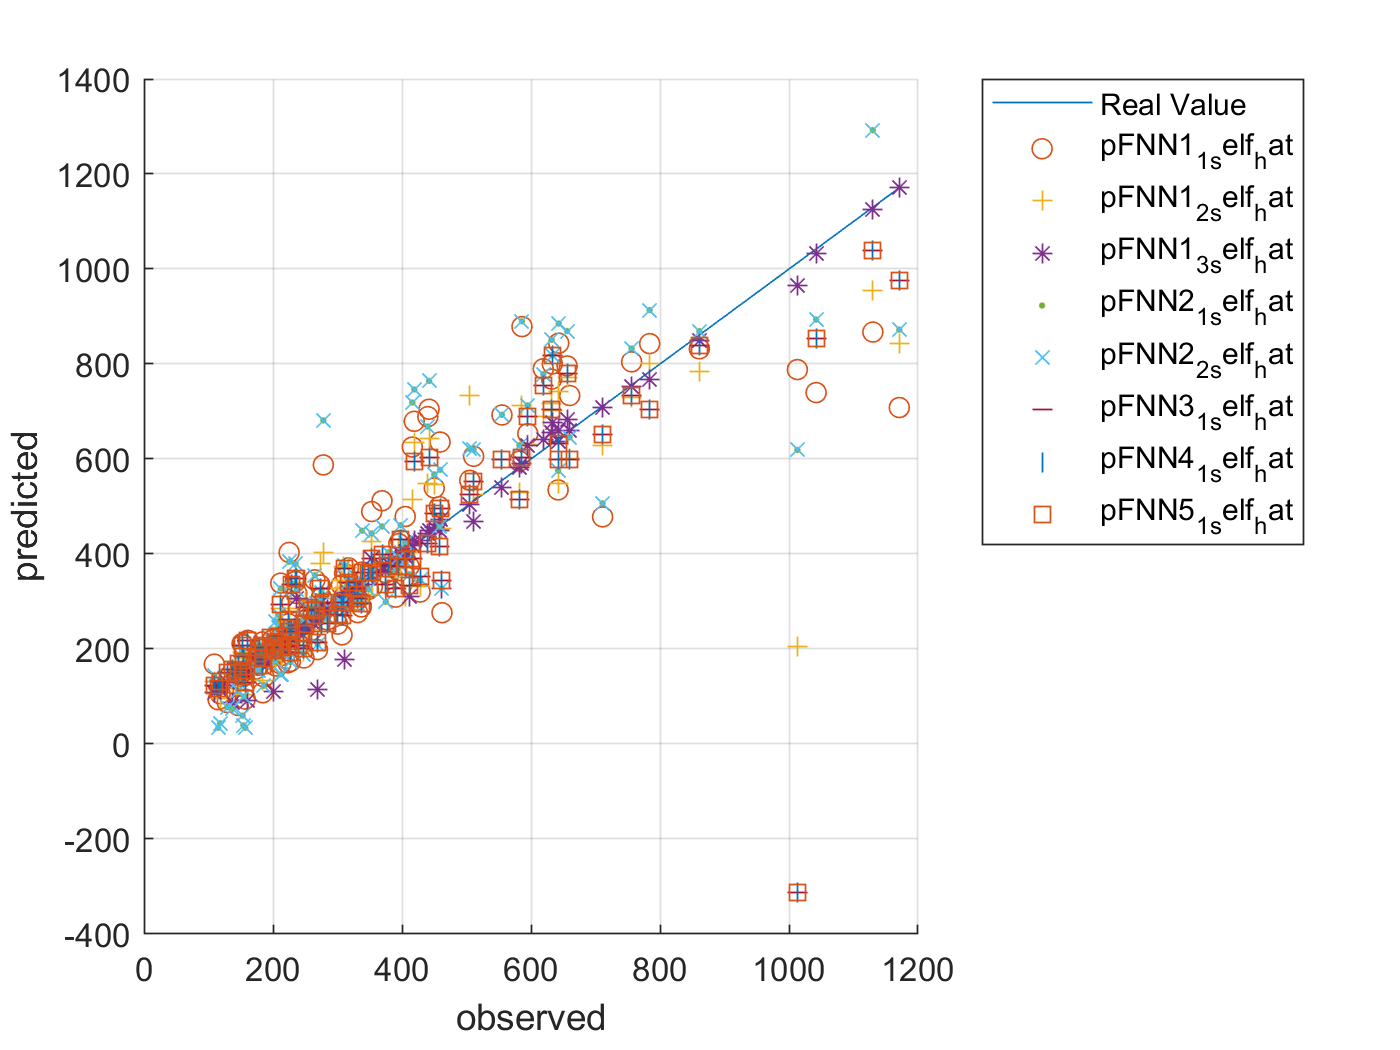




figure, hold on, grid on,
plot(ytrain_self,ytrain_self)
plot(ytrain_self,pFNN1_1_self_hat,'o')
plot(ytrain_self,pFNN1_2_self_hat,'+')
plot(ytrain_self,pFNN1_3_self_hat,'*')
plot(ytrain_self,pFNN2_1_self_hat,'.')
plot(ytrain_self,pFNN2_2_self_hat,'x')
plot(ytrain_self,pFNN3_1_self_hat,'_')
plot(ytrain_self,pFNN4_1_self_hat,'|')
plot(ytrain_self,pFNN5_1_self_hat,'s')
hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pFNN1_1_self_hat', ... 
		'pFNN1_2_self_hat', ...
		'pFNN1_3_self_hat', ... 	
		'pFNN2_1_self_hat', ... 
		'pFNN2_2_self_hat', ... 
		'pFNN3_1_self_hat', ... 
		'pFNN4_1_self_hat', ... 
		'pFNN5_1_self_hat','Location','northeastoutside')

# CNN 모델 생성

filterSize = 3;
numFilters = 32;
numFCN = 1;
cc_input_size = 20;

- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:08 |         0.34 |         0.33 |       0.0582 |       0.0535 |          0.0010 |
|      50 |          50 |       00:00:13 |         0.16 |         0.16 |       0.0129 |       0.0132 |          0.0010 |
|     100 |         100 |       00:00:16 |         0.13 |         0.12 |       0.0088 |       0.0066 |          0.0010 |
|     150 |         150 |       00:00:18 |         0.13 |         0.11 |       0.0081 |   

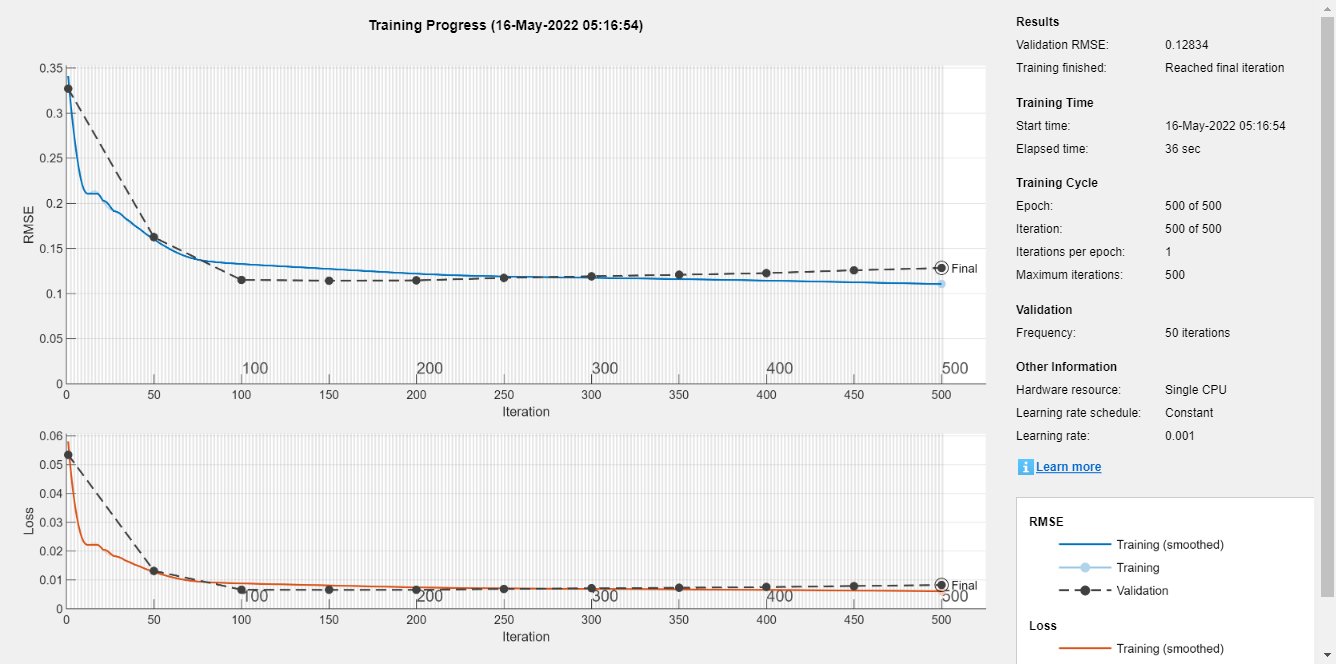

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:05 |         0.32 |         0.28 |       0.0502 |       0.0405 |          0.0010 |
|      50 |          50 |       00:00:08 |         0.14 |         0.14 |       0.0100 |       0.0100 |          0.0010 |
|     100 |         100 |       00:00:09 |         0.10 |         0.09 |       0.0049 |       0.0043 |          0.0010 |
|     150 |         150 |       00:00:11 |         0.09 |         0.09 |       0.0040 |   

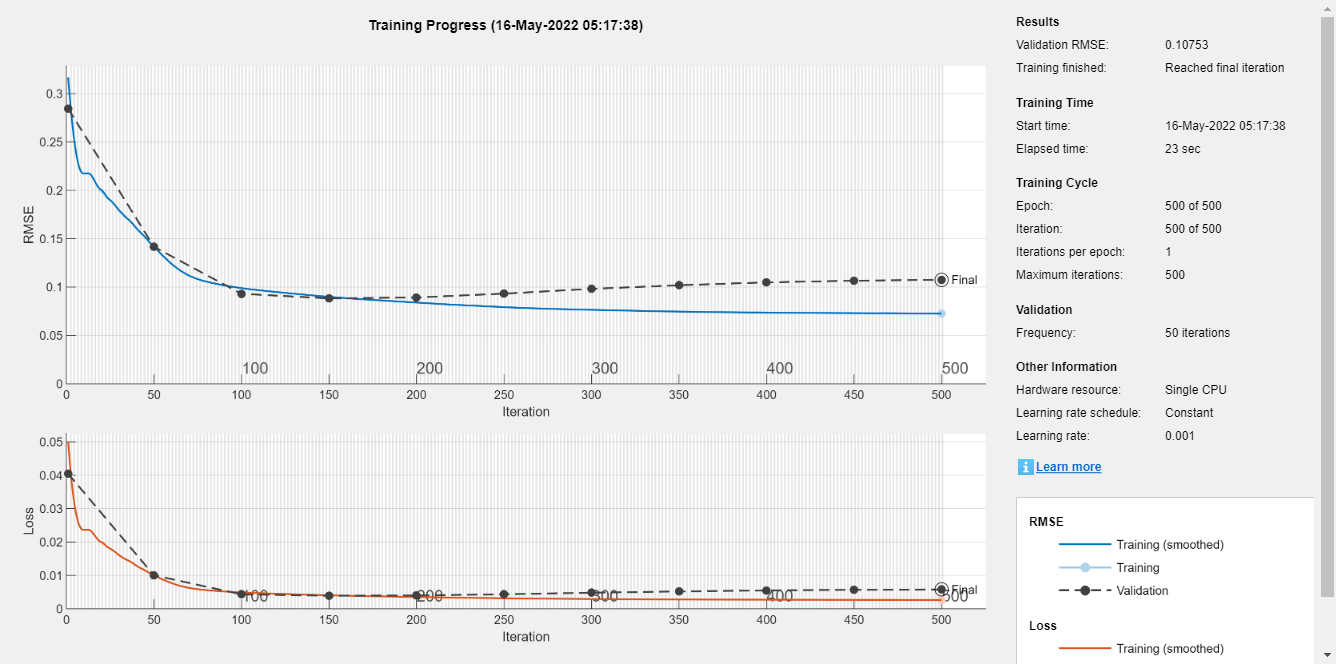

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:05 |         0.37 |         0.36 |       0.0683 |       0.0634 |          0.0010 |
|      50 |          50 |       00:00:10 |         0.18 |         0.19 |       0.0164 |       0.0174 |          0.0010 |
|     100 |         100 |       00:00:12 |         0.14 |         0.14 |       0.0091 |       0.0093 |          0.0010 |
|     150 |         150 |       00:00:14 |         0.11 |         0.11 |       0.0065 |   

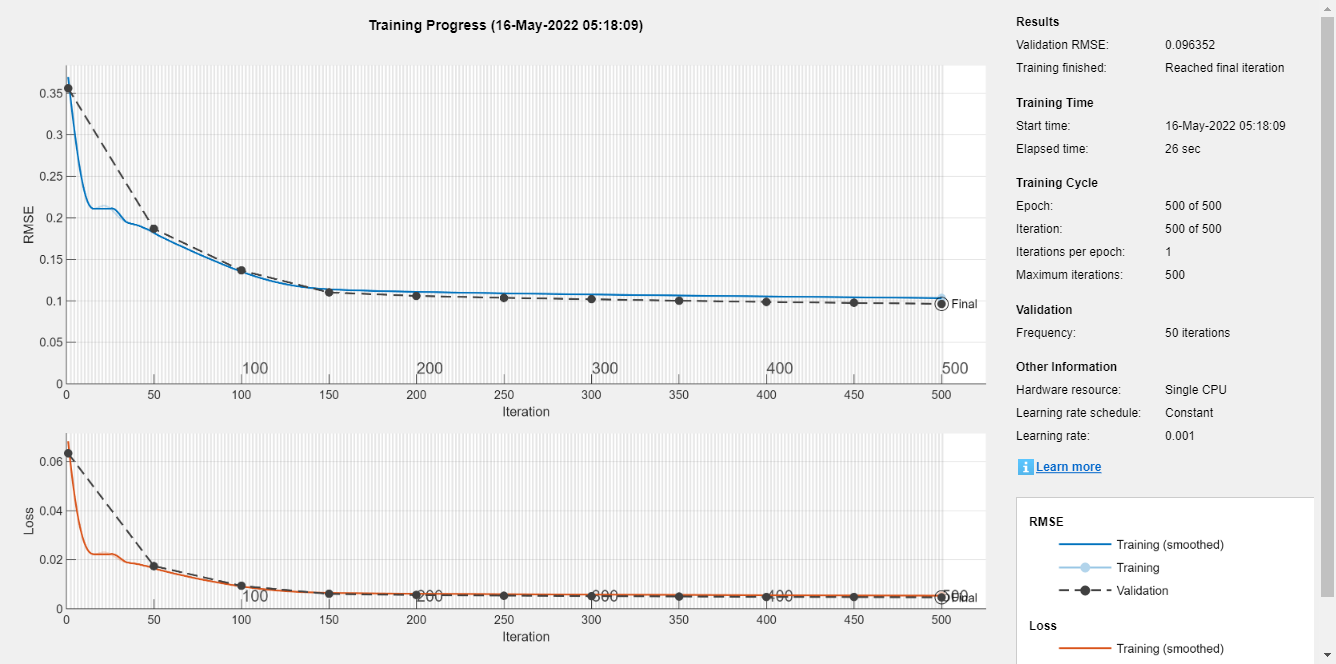

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:10 |         1.41 |         0.96 |       0.9885 |       0.4595 |          0.0010 |
|      50 |          50 |       00:00:13 |         0.14 |         0.13 |       0.0092 |       0.0085 |          0.0010 |
|     100 |         100 |       00:00:17 |         0.12 |         0.10 |       0.0071 |       0.0054 |          0.0010 |
|     150 |         150 |       00:00:23 |         0.12 |         0.10 |       0.0068 |   

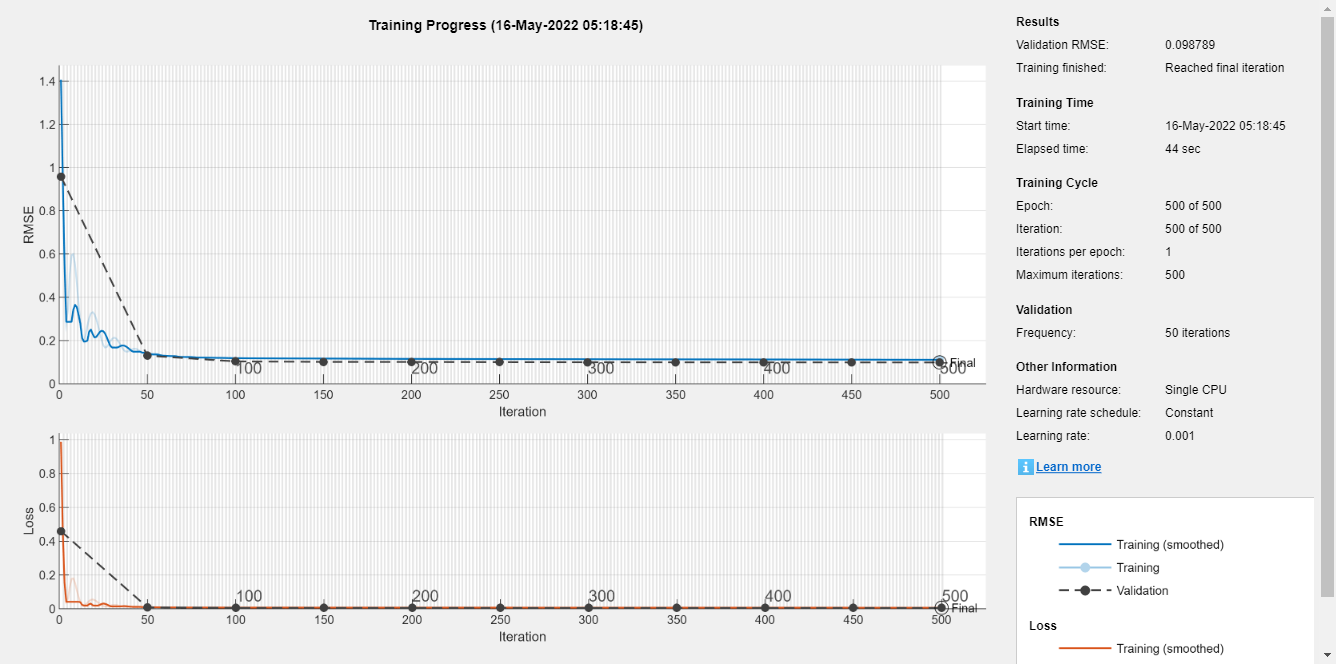

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:12 |         1.22 |         1.26 |       0.7406 |       0.7924 |          0.0010 |
|      50 |          50 |       00:00:17 |         0.14 |         0.12 |       0.0100 |       0.0073 |          0.0010 |
|     100 |         100 |       00:00:20 |         0.13 |         0.12 |       0.0087 |       0.0069 |          0.0010 |
|     150 |         150 |       00:00:24 |         0.13 |         0.11 |       0.0079 |   

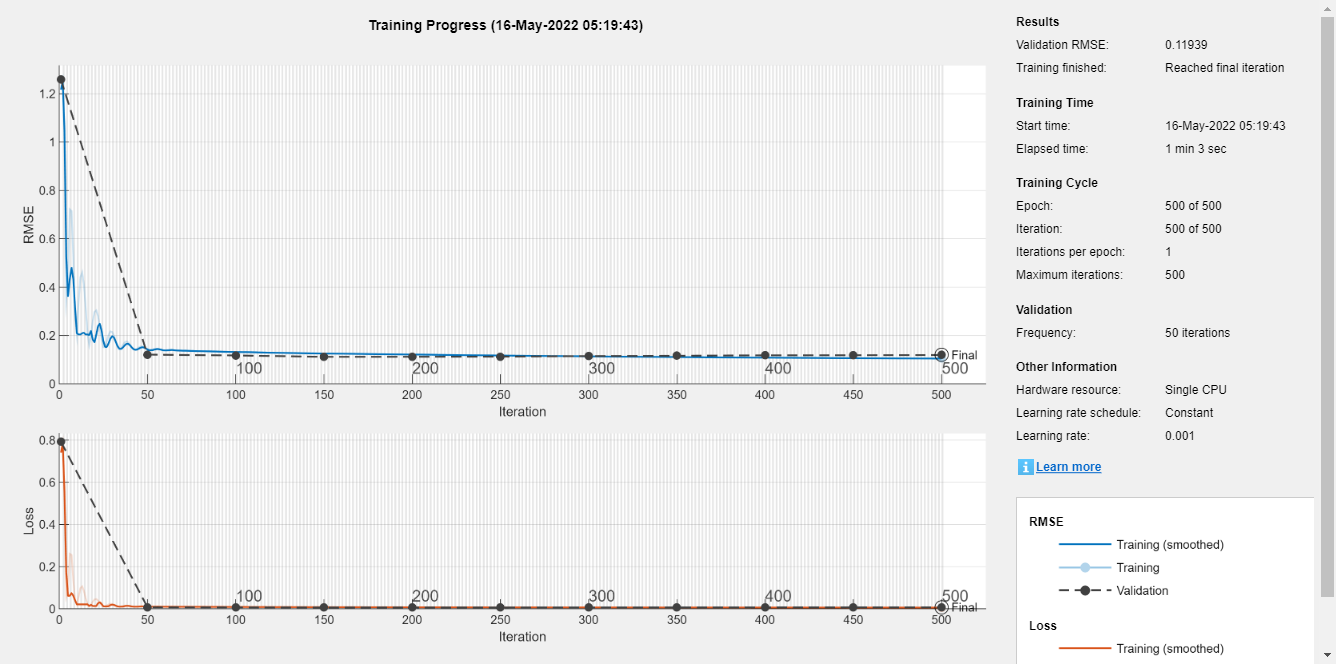

if generate_model

layerCNN2_1 = [
    imageInputLayer([1, cc_input_size]);
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(numFCN)
    regressionLayer();
    ];
cellx = num2cell(xnorm_VdFirst_RUL', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
cellyB = num2cell(ynorm_VdFirst_RUL);
tbl = table(cellx);
tbl.cellyB = cellyB;


Traintbl = tbl(tr.trainInd, :);
valtbl = tbl(tr.valInd, :);
testtbl = tbl(tr.testInd, :);

options = trainingOptions('adam', ...
 'InitialLearnRate', 0.001, ...
 'MaxEpochs',500, ...
 'MiniBatchSize',50, ...
 'Plots','training-progress', 'ValidationData', valtbl);

netCNN2_1 = trainNetwork(Traintbl, layerCNN2_1, options);




- CNN2 :2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

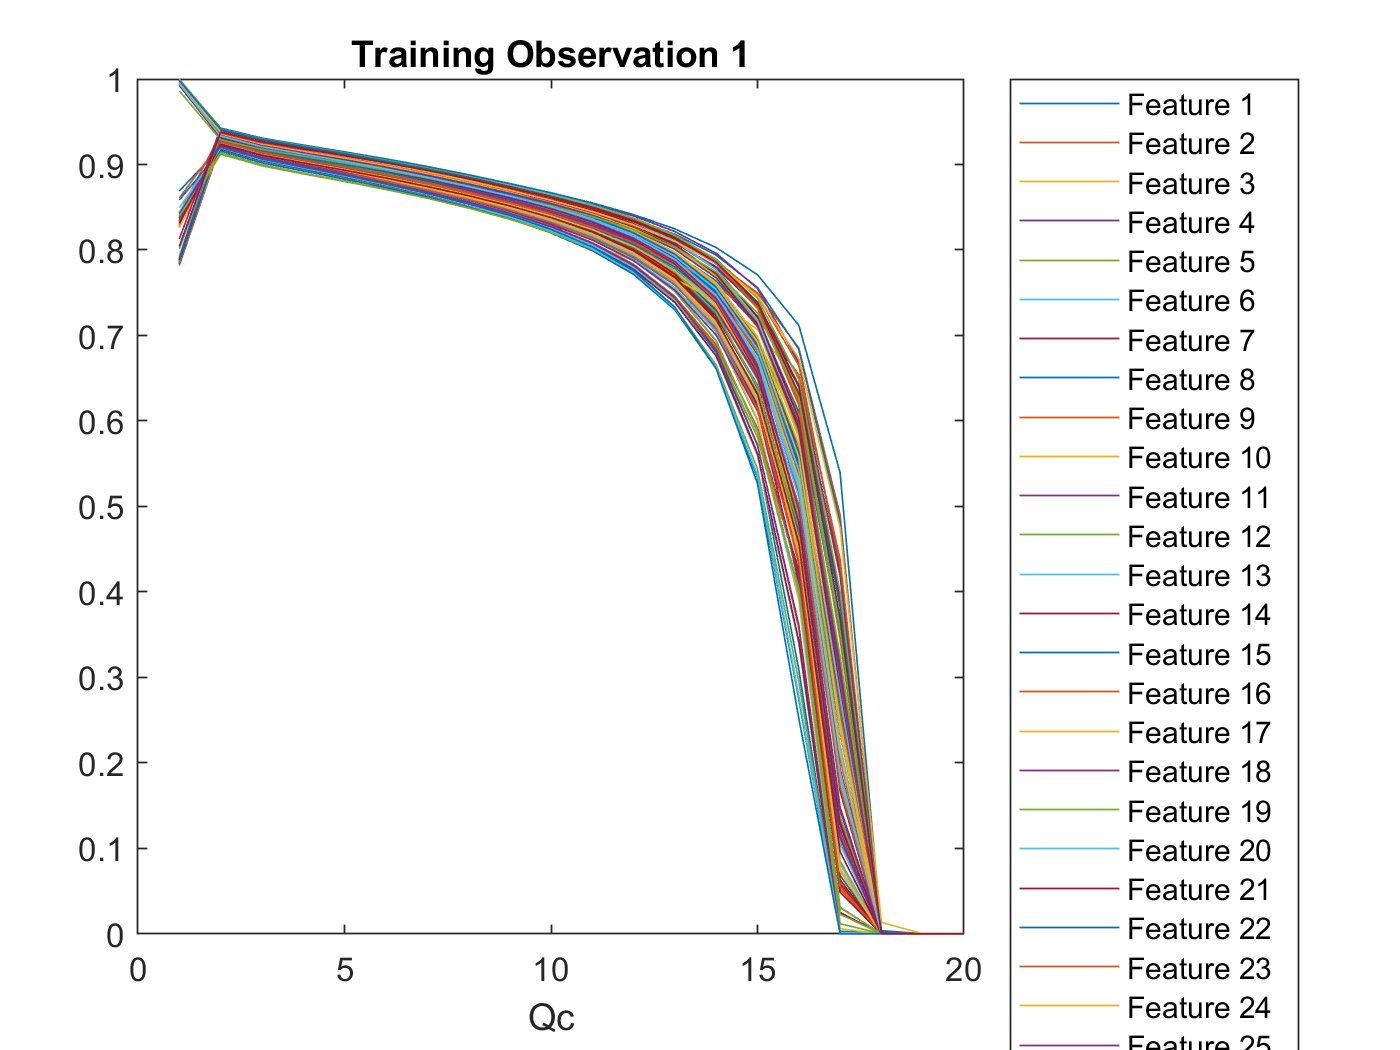

layerCNN2_2 = [
    imageInputLayer([1, cc_input_size]);
    convolution2dLayer([1, 2*filterSize], 2*numFilters, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2*filterSize], 2*numFilters, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(numFCN)
    regressionLayer();
    ];

netCNN2_2 = trainNetwork(Traintbl, layerCNN2_1, options);


layerCNN1_1 = [
    imageInputLayer([1, cc_input_size]);
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(numFCN)
    regressionLayer();
    ];
%     sequenceInputLayer(input_size)
%     convolution1dLayer(filterSize,numFilters)
%     reluLayer
%     globalMaxPooling1dLayer

pCNN2_1 = 12×1 single column vector
    0.1648
    0.1447
    0.1813
    0.0885
    0.0477
    0.0816
    0.0040
    0.5150
    0.3064
    0.3269


%     fullyConnectedLayer(numFCN)

pCNN2_2 = 12×1 single column vector
    0.1969
    0.1570
    0.2027
    0.1006
    0.0402
    0.0831
    0.0247
    0.6167
    0.2764
    0.2851


%     %softmaxLayer

pCNN2_3 = 12×1 single column vector
    0.2228
    0.1672
    0.2215
    0.1319
    0.0292
    0.1105
   -0.0617
    0.5296
    0.3207
    0.3339


%     regressionLayer();]

pCNN2_4 = 12×1 single column vector
    0.2039
    0.1575
    0.2182
    0.0808
    0.0458
    0.0817
    0.0502
    0.5283
    0.3205
    0.3434


netCNN1_1 = trainNetwork(Traintbl, layerCNN1_1, options);

pCNN1_1 = 12×1 single column vector
    0.1993
    0.1524
    0.2014
    0.1111
    0.0103
    0.0883
   -0.0756
    0.5370
    0.3091
    0.3278




layerCNN2_3 = [ ...
    imageInputLayer([1, cc_input_size]);
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    reluLayer
    layerNormalizationLayer
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    reluLayer
    layerNormalizationLayer
    globalAveragePooling2dLayer
    fullyConnectedLayer(numFCN)

rmse_pCNN2_1_hat = single
138.2619

    %softmaxLayer

rmse_pCNN2_2_hat = single
255.4071

    regressionLayer();];

rmse_pCNN2_3_hat = single
152.1286

netCNN2_3 = trainNetwork(Traintbl, layerCNN2_3, options);

rmse_pCNN2_4_hat = single
125.4791

rmse_pCNN1_1_hat = single
169.6505

layerCNN2_4 = [ ...

y_test_diff_percentage_CNN2_1_hat_avg = single
40.7087

    imageInputLayer([1, cc_input_size]);

y_test_diff_percentage_CNN2_2_hat_avg = single
53.6889

    convolution2dLayer([1, 2*filterSize], 2*numFilters, 'Stride', 1);

y_test_diff_percentage_CNN2_3_hat_avg = single
51.1219

     reluLayer

y_test_diff_percentage_CNN2_4_hat_avg = single
44.8638

    layerNormalizationLayer

y_test_diff_percentage_CNN1_1_hat_avg = single
50.2581

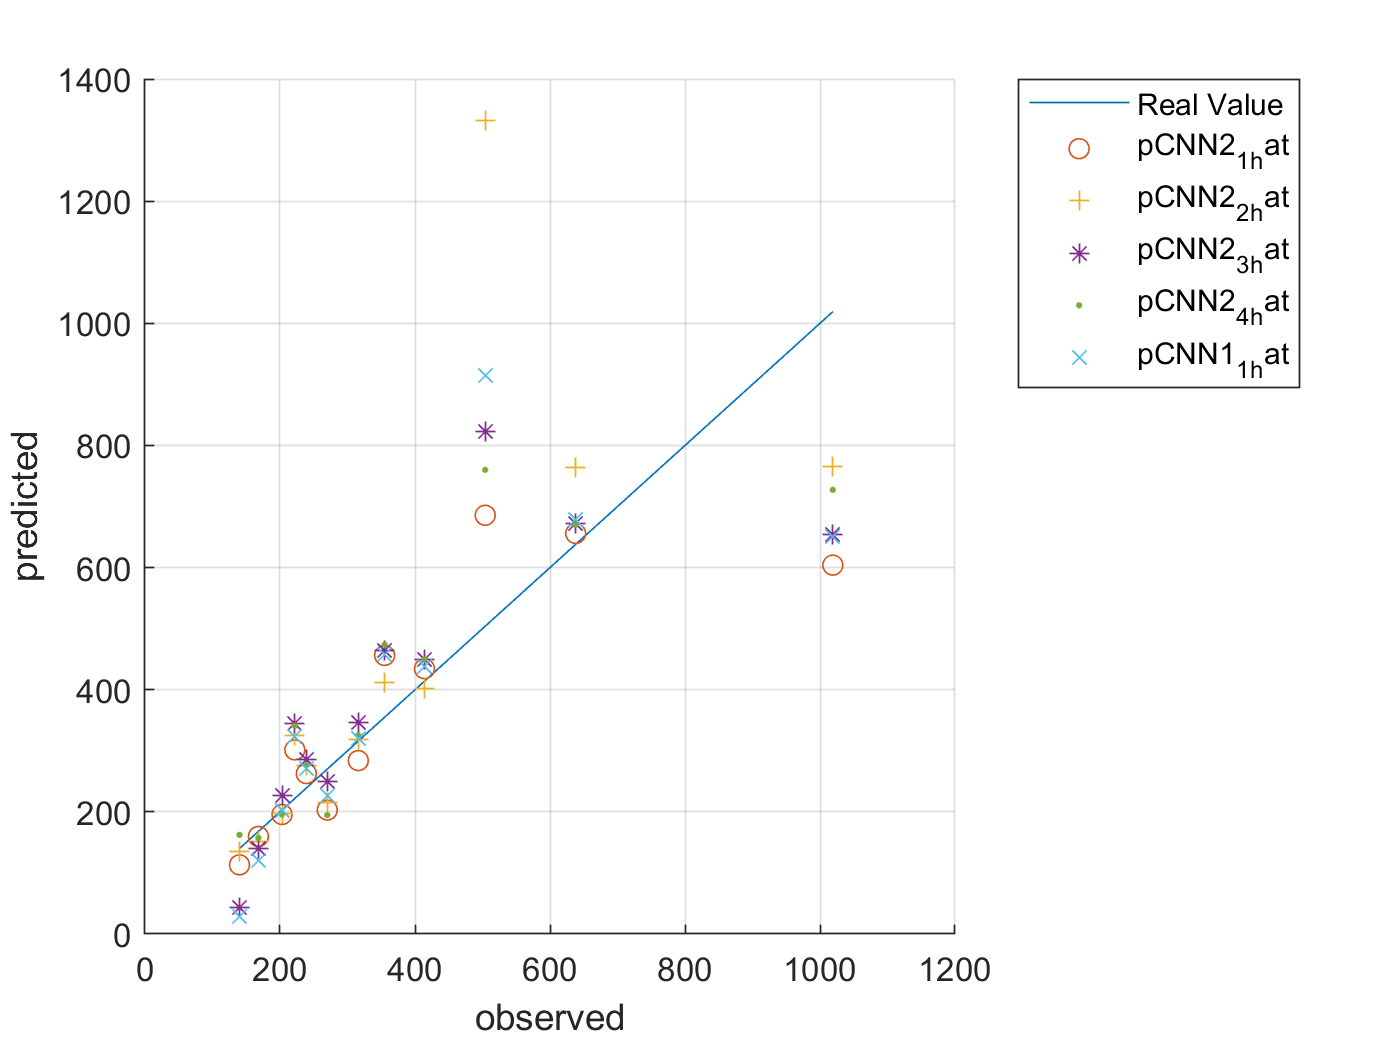

    convolution2dLayer([1, 2*filterSize], 2*numFilters, 'Stride', 1);
    reluLayer
    layerNormalizationLayer
    globalAveragePooling2dLayer
    fullyConnectedLayer(numFCN)
    %softmaxLayer
    regressionLayer();];
netCNN2_4 = trainNetwork(Traintbl, layerCNN2_4, options);

save('ryan3_model_FirstVd_RUL.mat','netCNN2_1' ,'-append')
save('ryan3_model_FirstVd_RUL.mat','netCNN2_2' ,'-append')
save('ryan3_model_FirstVd_RUL.mat','netCNN2_3' ,'-append')
save('ryan3_model_FirstVd_RUL.mat','netCNN2_4' ,'-append')
save('ryan3_model_FirstVd_RUL.mat','netCNN1_1' ,'-append')

end

# CNN 예측

filterSize = 3;
numFilters = 32;
numFCN = 1;
cc_input_size = 20;

figure
plot(xnorm_VdFirst_RUL')
xlabel("Qc")
title("Training Observation 1")
numFeatures = size(xnorm_VdFirst_RUL,1);
legend("Feature " + string(1:numFeatures),Location="northeastoutside")


cellx = num2cell(xnorm_VdFirst_RUL(idxTestSort, :)', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);

x_4d = zeros(1, cc_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN2_1 = predict(netCNN2_1, x_4d)
pCNN2_2 = predict(netCNN2_2, x_4d)
pCNN2_3 = predict(netCNN2_3, x_4d)

rmse_pCNN2_1_self_hat = single
112.8624

pCNN2_4 = predict(netCNN2_4, x_4d)

rmse_pCNN2_2_self_hat = single
126.9312

pCNN1_1 = predict(netCNN1_1, x_4d)

rmse_pCNN2_3_self_hat = single
119.1028

rmse_pCNN2_4_self_hat = single
112.7064

rmse_pCNN1_1_self_hat = single
118.3552

ytrain_self_diff_percentage_CNN2_1_self_hat_avg = single
19.3540

ytest = ynorm_VdFirst_RUL(idxTestSort, :)*yrate_First_RUL + ymin_First_RUL;

ytrain_self_diff_percentage_CNN2_2_self_hat_avg = single
20.3658

pCNN2_1_hat = pCNN2_1 * yrate_First_RUL + ymin_First_RUL;

ytrain_self_diff_percentage_CNN2_3_self_hat_avg = single
24.8459

pCNN2_2_hat = pCNN2_2 * yrate_First_RUL + ymin_First_RUL;

ytrain_self_diff_percentage_CNN2_4_self_hat_avg = single
20.7814

pCNN2_3_hat = pCNN2_3 * yrate_First_RUL + ymin_First_RUL;

ytrain_self_diff_percentage_CNN1_1_self_hat_avg = single
25.5605

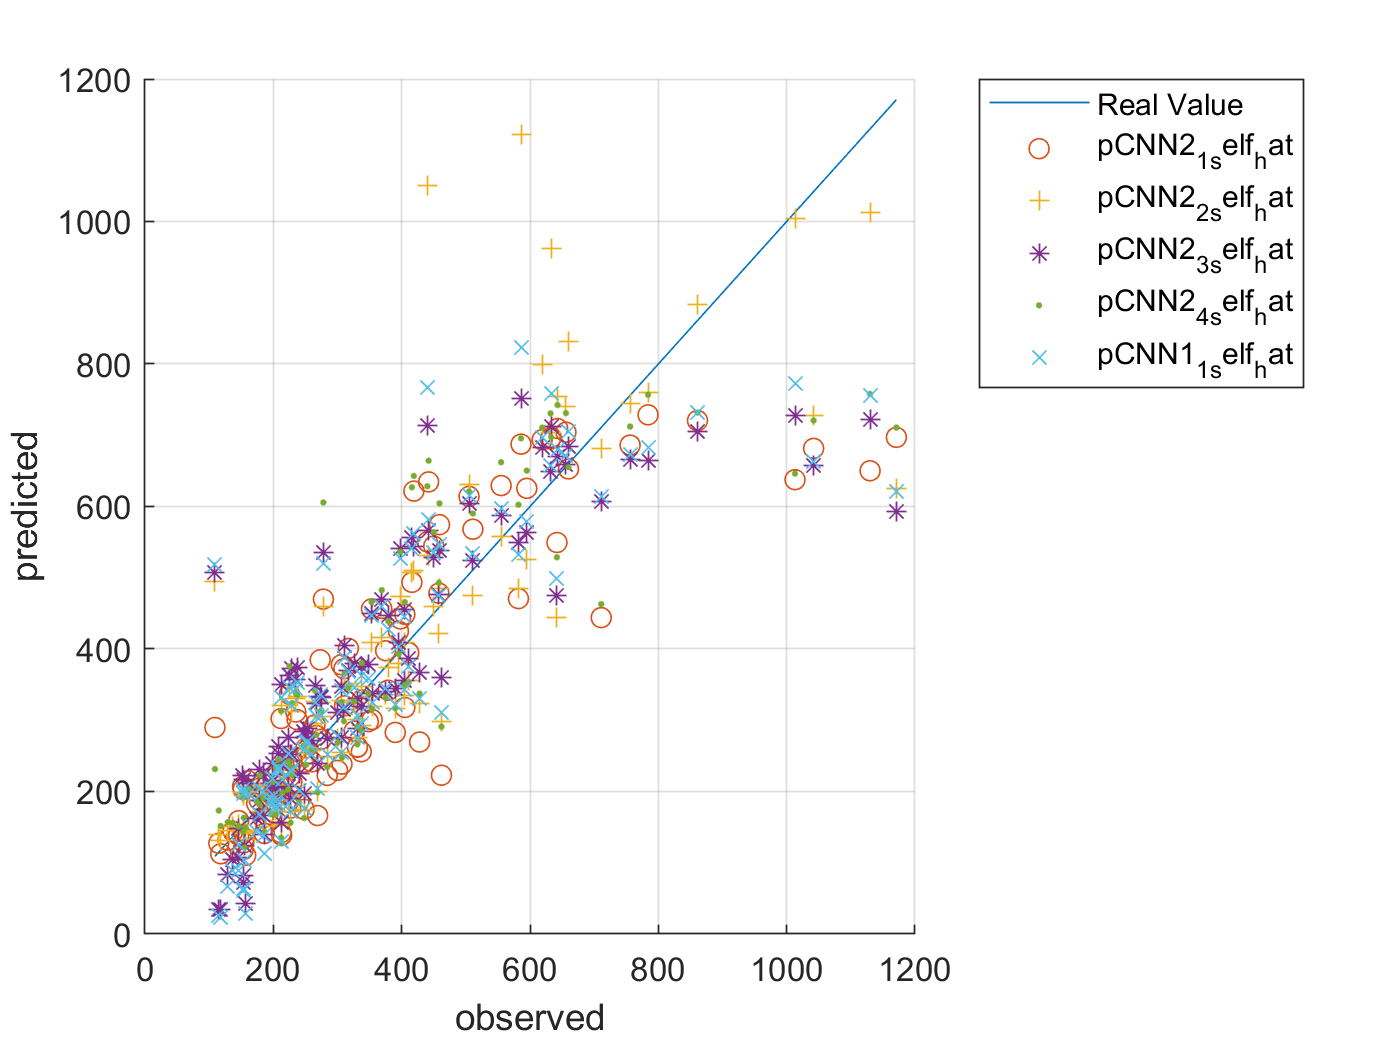

pCNN2_4_hat = pCNN2_4 * yrate_First_RUL + ymin_First_RUL;
pCNN1_1_hat = pCNN1_1 * yrate_First_RUL + ymin_First_RUL;


rmse_pCNN2_1_hat = sqrt(mean(( ytest' - pCNN2_1_hat' ).^2))
rmse_pCNN2_2_hat = sqrt(mean(( ytest' - pCNN2_2_hat' ).^2))
rmse_pCNN2_3_hat = sqrt(mean(( ytest' - pCNN2_3_hat' ).^2))
rmse_pCNN2_4_hat = sqrt(mean(( ytest' - pCNN2_4_hat' ).^2))
rmse_pCNN1_1_hat = sqrt(mean(( ytest' - pCNN1_1_hat' ).^2))
y_test_diff_percentage_CNN2_1_hat_avg = sum(abs(Y_test_VdFirst_RUL'-pCNN2_1_hat')./Y_test_VdFirst_RUL'.*100)/length(abs(Y_test_VdFirst_RUL'-pCNN2_1_hat')./Y_test_VdFirst_RUL')
y_test_diff_percentage_CNN2_2_hat_avg = sum(abs(Y_test_VdFirst_RUL'-pCNN2_2_hat')./Y_test_VdFirst_RUL'.*100)/length(abs(Y_test_VdFirst_RUL'-pCNN2_2_hat')./Y_test_VdFirst_RUL')
y_test_diff_percentage_CNN2_3_hat_avg = sum(abs(Y_test_VdFirst_RUL'-pCNN2_3_hat')./Y_test_VdFirst_RUL'.*100)/length(abs(Y_test_VdFirst_RUL'-pCNN2_3_hat')./Y_test_VdFirst_RUL')
y_test_diff_percentage_CNN2_4_hat_avg = sum(abs(Y_test_VdFirst_RUL'-pCNN2_4_hat')./Y_test_VdFirst_RUL'.*100)/length(abs(Y_test_VdFirst_RUL'-pCNN2_4_hat')./Y_test_VdFirst_RUL')
y_test_diff_percentage_CNN1_1_hat_avg = sum(abs(Y_test_VdFirst_RUL'-pCNN1_1_hat')./Y_test_VdFirst_RUL'.*100)/length(abs(Y_test_VdFirst_RUL'-pCNN1_1_hat')./Y_test_VdFirst_RUL')



figure, hold on, grid on,
plot(ytest,ytest)
plot(ytest,pCNN2_1_hat,'o')

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:11 |         0.25 |         0.23 |       0.0310 |       0.0264 |          0.0010 |
|      50 |          50 |       00:00:18 |         0.19 |         0.18 |       0.0179 |       0.0170 |          0.0010 |
|     100 |         100 |       00:00:21 |         0.15 |         0.13 |       0.0108 |       0.0082 |          0.0010 |
|     150 |         150 |       00:00:25 |         0.13 |         0.10 |       0.0087 |       0.0050 |          0.0010 |
|     20

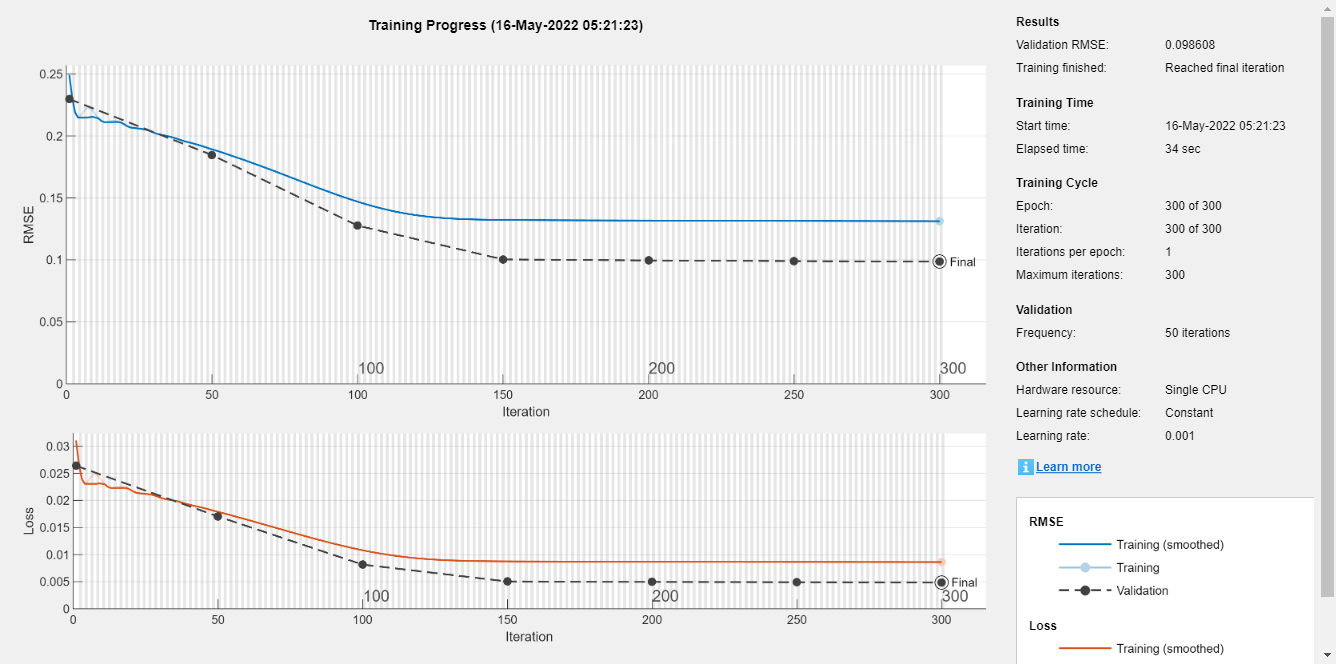

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:07 |         0.34 |         0.32 |       0.0582 |       0.0506 |          0.0010 |
|      50 |          50 |       00:00:19 |         0.22 |         0.21 |       0.0245 |       0.0226 |          0.0010 |
|     100 |         100 |       00:00:26 |         0.20 |         0.18 |       0.0191 |       0.0162 |          0.0010 |
|     150 |         150 |       00:00:32 |         0.15 |         0.10 |       0.0116 |       0.0051 |          0.0010 |
|     20

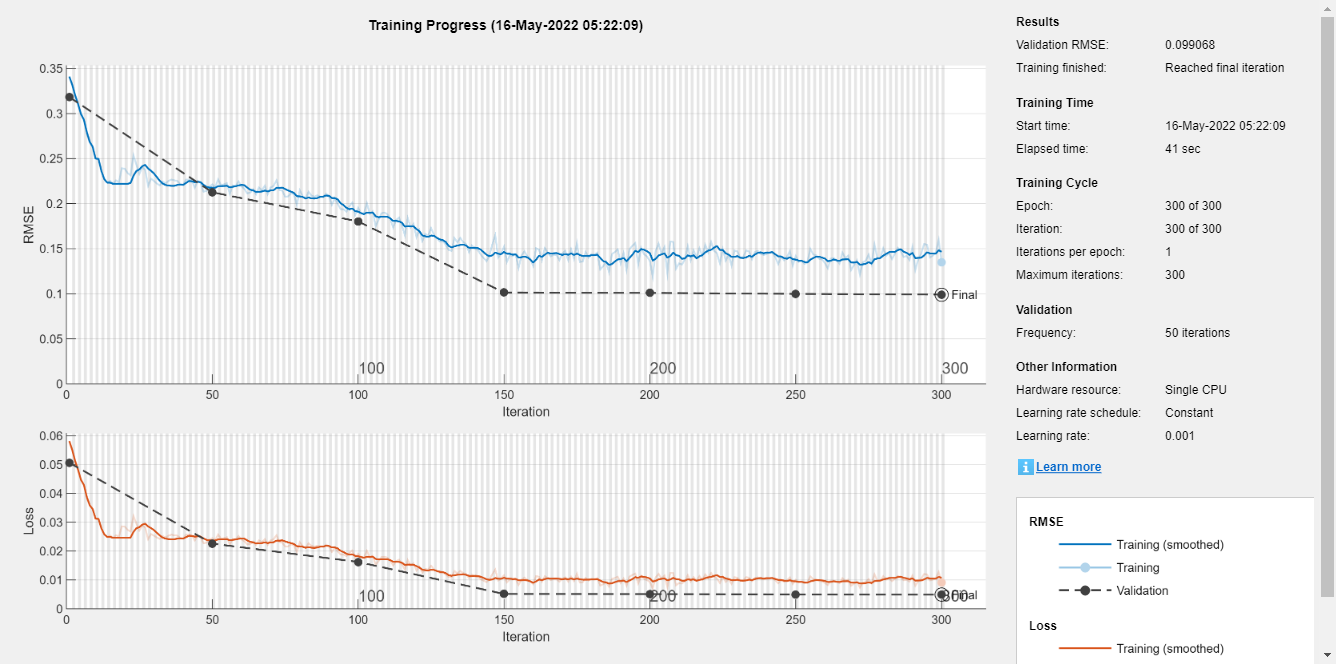

plot(ytest,pCNN2_2_hat,'+')
plot(ytest,pCNN2_3_hat,'*')
plot(ytest,pCNN2_4_hat,'.')
plot(ytest,pCNN1_1_hat,'x')

hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pCNN2_1_hat', ... 
		'pCNN2_2_hat', ...
		'pCNN2_3_hat', ... 	
		'pCNN2_4_hat', ... 
		'pCNN1_1_hat','Location','northeastoutside')




cellx_self = num2cell(xnorm_VdFirst_RUL([idxTrainSort idxValidSort], :)', 1)';
cellx_self = cellfun(@transpose, cellx_self, 'UniformOutput', false);
tbl_self = table(cellx_self);

x_4d_self = zeros(1, cc_input_size, 1, height(tbl_self));
for i = 1:height(tbl_self)
    x_4d_self(:,:,:,i) = tbl_self.cellx_self{i};
end

pCNN2_1_self = predict(netCNN2_1, x_4d_self);
pCNN2_2_self = predict(netCNN2_2, x_4d_self);
pCNN2_3_self = predict(netCNN2_3, x_4d_self);
pCNN2_4_self = predict(netCNN2_4, x_4d_self);
pCNN1_1_self = predict(netCNN1_1, x_4d_self);


rmse_pLSTM1_hat = single
175.9186

ytrain_self = ynorm_VdFirst_RUL([idxTrainSort idxValidSort], :)*yrate_First_RUL + ymin_First_RUL;

rmse_pLSTM2_hat = single
214.0682

pCNN2_1_self_hat = pCNN2_1_self * yrate_First_RUL + ymin_First_RUL;

y_test_diff_percentage_LSTM_hat_avg = single
50.3020

pCNN2_2_self_hat = pCNN2_2_self * yrate_First_RUL + ymin_First_RUL;

y_test_diff_percentage_LSTM2_hat_avg = single
76.2250

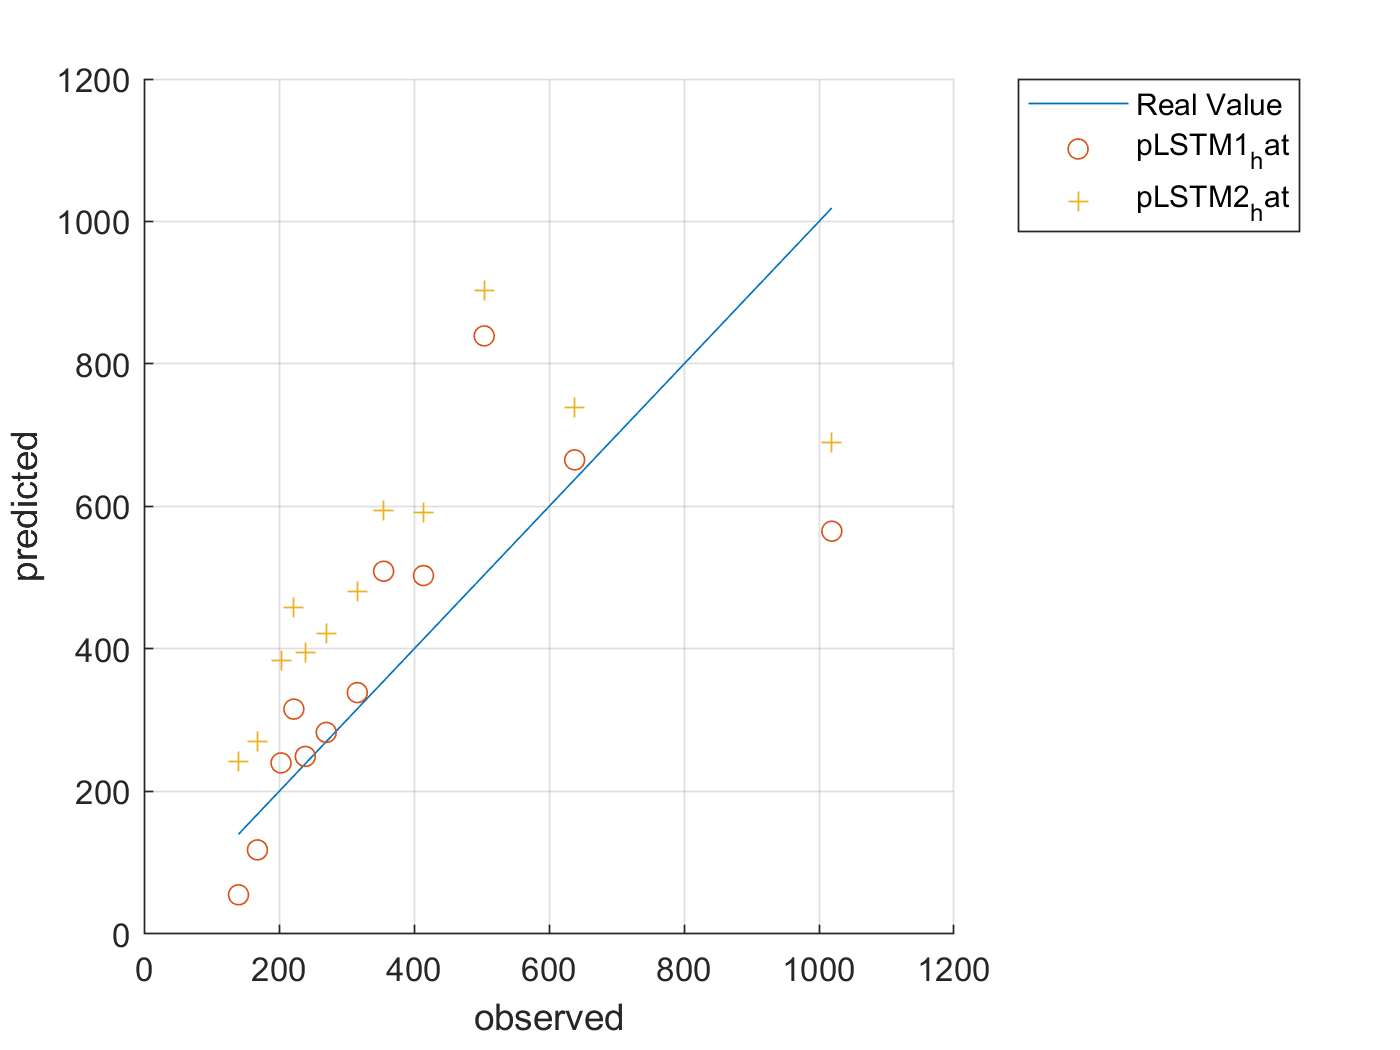

pCNN2_3_self_hat = pCNN2_3_self * yrate_First_RUL + ymin_First_RUL;
pCNN2_4_self_hat = pCNN2_4_self * yrate_First_RUL + ymin_First_RUL;
pCNN1_1_self_hat = pCNN1_1_self * yrate_First_RUL + ymin_First_RUL;



rmse_pCNN2_1_self_hat = sqrt(mean(( ytrain_self' - pCNN2_1_self_hat' ).^2))
rmse_pCNN2_2_self_hat = sqrt(mean(( ytrain_self' - pCNN2_2_self_hat' ).^2))
rmse_pCNN2_3_self_hat = sqrt(mean(( ytrain_self' - pCNN2_3_self_hat' ).^2))
rmse_pCNN2_4_self_hat = sqrt(mean(( ytrain_self' - pCNN2_4_self_hat' ).^2))
rmse_pCNN1_1_self_hat = sqrt(mean(( ytrain_self' - pCNN1_1_self_hat' ).^2))
ytrain_self_diff_percentage_CNN2_1_self_hat_avg = sum(abs(ytrain_self'-pCNN2_1_self_hat')./ytrain_self'.*100)/length(abs(ytrain_self'-pCNN2_1_self_hat')./ytrain_self')

ytrain_self_diff_percentage_CNN2_2_self_hat_avg = sum(abs(ytrain_self'-pCNN2_2_self_hat')./ytrain_self'.*100)/length(abs(ytrain_self'-pCNN2_2_self_hat')./ytrain_self')
ytrain_self_diff_percentage_CNN2_3_self_hat_avg = sum(abs(ytrain_self'-pCNN2_3_self_hat')./ytrain_self'.*100)/length(abs(ytrain_self'-pCNN2_3_self_hat')./ytrain_self')
ytrain_self_diff_percentage_CNN2_4_self_hat_avg = sum(abs(ytrain_self'-pCNN2_4_self_hat')./ytrain_self'.*100)/length(abs(ytrain_self'-pCNN2_4_self_hat')./ytrain_self')
ytrain_self_diff_percentage_CNN1_1_self_hat_avg = sum(abs(ytrain_self'-pCNN1_1_self_hat')./ytrain_self'.*100)/length(abs(ytrain_self'-pCNN1_1_self_hat')./ytrain_self')


figure, hold on, grid on,
plot(ytrain_self,ytrain_self)
plot(ytrain_self,pCNN2_1_self_hat,'o')

rmse_pLSTM1_self_hat = single
129.7948

plot(ytrain_self,pCNN2_2_self_hat,'+')

rmse_pLSTM2_self_hat = single
130.4696

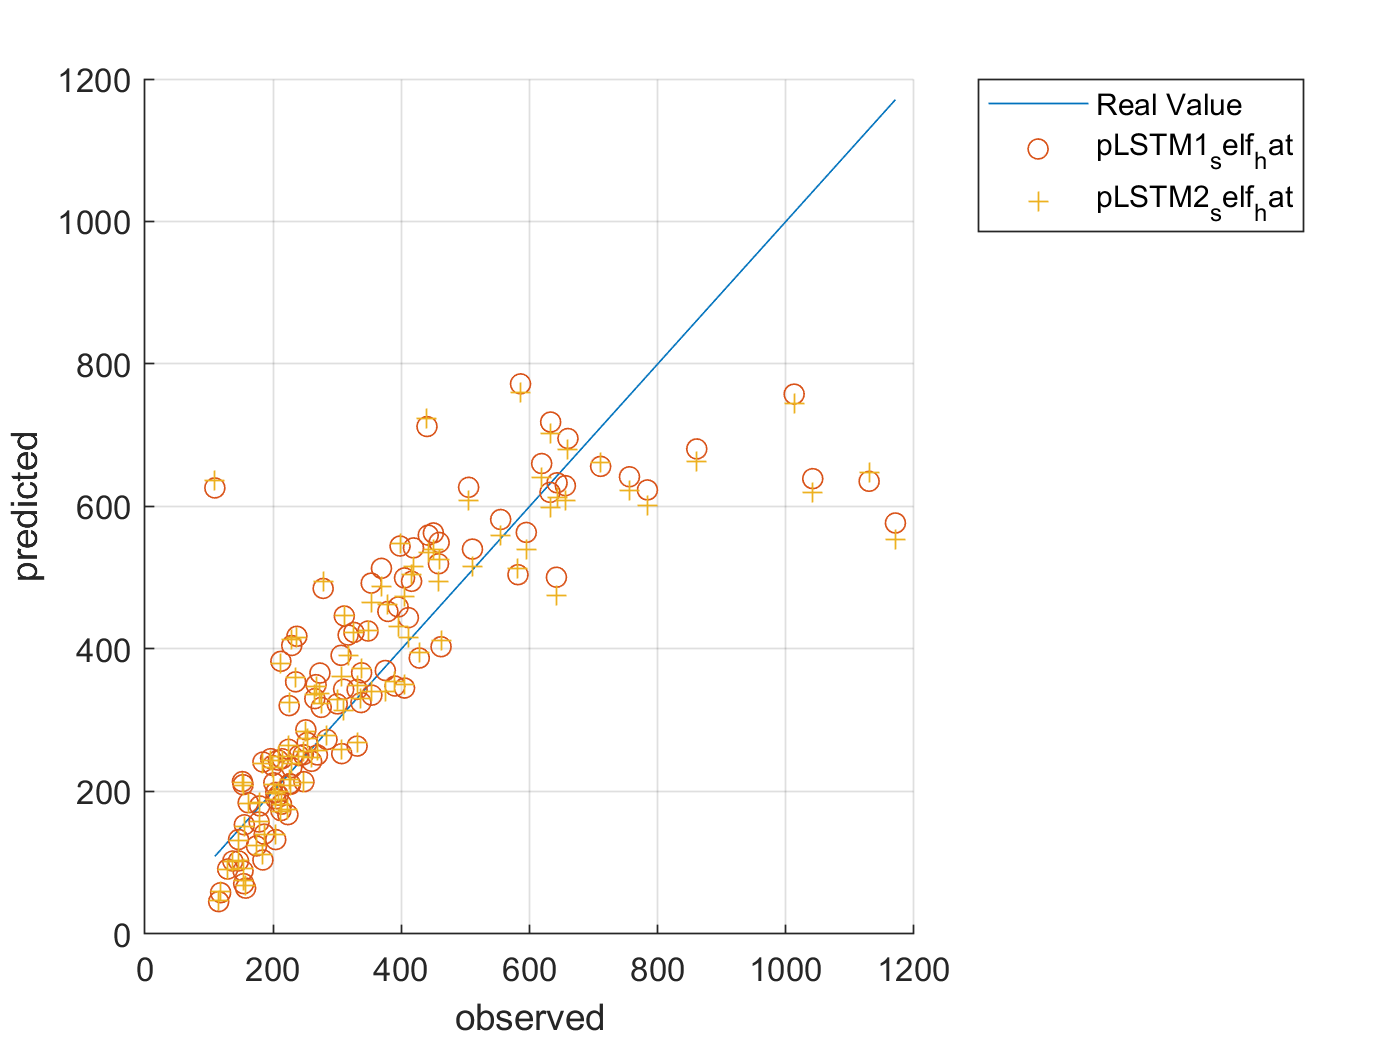

plot(ytrain_self,pCNN2_3_self_hat,'*')
plot(ytrain_self,pCNN2_4_self_hat,'.')
plot(ytrain_self,pCNN1_1_self_hat,'x')

hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pCNN2_1_self_hat', ... 
		'pCNN2_2_self_hat', ...
		'pCNN2_3_self_hat', ... 	

		'pCNN2_4_self_hat', ... 
		'pCNN1_1_self_hat','Location','northeastoutside')



# LSTM 모델 생성

- LSTM : 1 lstm layer with 5 hidden units

cc_input_size = 20;
numHiddenUnits = 50;

if generate_model
    
layersLSTM1 = [ ...
    sequenceInputLayer(cc_input_size)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(1)
    regressionLayer
    ];

layersLSTM2 = [ ...
    sequenceInputLayer(cc_input_size)
    lstmLayer(numHiddenUnits)
    dropoutLayer(0.2)
    lstmLayer(numHiddenUnits)
    dropoutLayer(0.2)
    fullyConnectedLayer(1)
    regressionLayer
    ];

cellx = num2cell(xnorm_VdFirst_RUL', 1)';
cellyB = num2cell(ynorm_VdFirst_RUL);

traincellx = cellx(tr.trainInd, :);
valcellx = cellx(tr.valInd, :);
testcellx = cellx(tr.testInd, :);

traincellyB = cellyB(tr.trainInd, :);
valcellyB = cellyB(tr.valInd, :);
testcellyB = cellyB(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',300, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

netLSTM1 = trainNetwork(traincellx, traincellyB, layersLSTM1, options);
netLSTM2 = trainNetwork(traincellx, traincellyB, layersLSTM2, options);

save('ryan3_model_FirstVd_RUL.mat','netLSTM1' ,'-append')
save('ryan3_model_FirstVd_RUL.mat','netLSTM2' ,'-append')

end

# LSTM 예측

cc_input_size = 20;
numHiddenUnits = 50;

pLSTM1 = cell2mat(predict(netLSTM1, num2cell(xnorm_VdFirst_RUL(idxTestSort, :)', 1)));
pLSTM2 = cell2mat(predict(netLSTM2, num2cell(xnorm_VdFirst_RUL(idxTestSort, :)', 1)));
ytest = ynorm_VdFirst_RUL(idxTestSort, :)*yrate_First_RUL + ymin_First_RUL;
pLSTM1_hat = pLSTM1 * yrate_First_RUL + ymin_First_RUL;
pLSTM2_hat = pLSTM2 * yrate_First_RUL + ymin_First_RUL;
rmse_pLSTM1_hat = sqrt(mean(( ytest' - pLSTM1_hat' ).^2))
rmse_pLSTM2_hat = sqrt(mean(( ytest' - pLSTM2_hat' ).^2))
y_test_diff_percentage_LSTM_hat_avg = sum(abs(Y_test_VdFirst_RUL'-pLSTM1_hat')./Y_test_VdFirst_RUL'.*100)/length(abs(Y_test_VdFirst_RUL'-pLSTM1_hat')./Y_test_VdFirst_RUL')
y_test_diff_percentage_LSTM2_hat_avg = sum(abs(Y_test_VdFirst_RUL'-pLSTM2_hat')./Y_test_VdFirst_RUL'.*100')/length(abs(Y_test_VdFirst_RUL'-pLSTM2_hat')./Y_test_VdFirst_RUL')

figure, hold on, grid on,
plot(ytest,ytest)
plot(ytest,pLSTM1_hat,'o')
plot(ytest,pLSTM2_hat,'+')
hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pLSTM1_hat', ...
        'pLSTM2_hat','Location','northeastoutside')



pLSTM1_self = cell2mat(predict(netLSTM1, num2cell(xnorm_VdFirst_RUL([idxTrainSort idxValidSort], :)', 1)));
pLSTM2_self = cell2mat(predict(netLSTM2, num2cell(xnorm_VdFirst_RUL([idxTrainSort idxValidSort], :)', 1)));
ytrain_self = ynorm_VdFirst_RUL([idxTrainSort idxValidSort], :)*yrate_First_RUL + ymin_First_RUL;
pLSTM1_self = pLSTM1_self * yrate_First_RUL + ymin_First_RUL;
pLSTM2_self = pLSTM2_self * yrate_First_RUL + ymin_First_RUL;
rmse_pLSTM1_self_hat = sqrt(mean(( ytrain_self' - pLSTM1_self' ).^2))
rmse_pLSTM2_self_hat = sqrt(mean(( ytrain_self' - pLSTM2_self' ).^2))

figure, hold on, grid on,
plot(ytrain_self,ytrain_self)
plot(ytrain_self,pLSTM1_self,'o')
plot(ytrain_self,pLSTM2_self,'+')
hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pLSTM1_self_hat', ...
        'pLSTM2_self_hat','Location','northeastoutside')
